## **HCP Main Sample - Internal Cross-Validation 'Expanded NMA Model' (176 frames)**

**Control Analysis**: All fMRI scans were shortened to 176 frames.Conduction of the internal-cross-validation of the ‘Expanded NMA Model’ that is built using 14 input predictor variables (Two from each of the seven task conditions). The predictor variables are derived from individual’s  coupling values and extracted by using group-based positive and group-based negative NMA masks. This script contains three parts: **Part 1** partitions the sample into five different folds (considering family relations and intelligence distribution) and creates positive and negative NMAs for each training fold and test fold. **Part 2 **uses the NMAs created in part 1 to build multiple linear regression models that are then tested for their ability to predict general intelligence in the test samples. Part 3 assesses the significance of the prediction with a permutation test.

Before running this script: 

- run all scripts in HCP Data Prep

**Part 1**

Partitioning the sample into 5 different folds and creating the condition-specific positive and negative NMAs for each training fold and test fold based on the correllation with general intelligence scores. 

**1.1. Prepare the coupling data for the emotion task**

1.1.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_emotion_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_emotion{i,j} = x(j,:);
    end
end

1.1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_emotion,2);
All_Nodes_complete_HCP_emotion = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_emotion{j} = vertcat(Node_all_baseline_HCP_emotion{:,j});
end 

1.1.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_emotion{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_emotion_4_measures{1,i} = four_measures_per_node;
end

**1.2. Prepare the coupling data for the gambling task **

1.2.1.  Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_gambling_176_frames_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_gambling{i,j} = x(j,:);
    end
end

1.2.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_gambling,2);
All_Nodes_complete_HCP_gambling = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_gambling{j} = vertcat(Node_all_baseline_HCP_gambling{:,j});
end 

1.2.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_gambling{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_gambling_4_measures{1,i} = four_measures_per_node;
end

**1.3. Prepare the coupling data for the language task**

1.3.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_language_176_frames_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_language{i,j} = x(j,:);
    end
end

1.3.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_language,2);
All_Nodes_complete_HCP_language = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_language{j} = vertcat(Node_all_baseline_HCP_language{:,j});
end 

1.3.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_language{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_language_4_measures{1,i} = four_measures_per_node;
end

**1.4. Prepare the coupling data for the motor task**

1.4.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_motor_176_frames_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_motor{i,j} = x(j,:);
    end
end

1.4.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_motor,2);
All_Nodes_complete_HCP_motor = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_motor{j} = vertcat(Node_all_baseline_HCP_motor{:,j});
end 

1.4.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_motor{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_motor_4_measures{1,i} = four_measures_per_node;
end

**1.5. Prepare the coupling data for the relational processing task**

1.5.1. Create cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_relational_176_frames_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_relational{i,j} = x(j,:);
    end
end

1.5.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_relational,2);
All_Nodes_complete_HCP_relational = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_relational{j} = vertcat(Node_all_baseline_HCP_relational{:,j});
end 

1.5.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_relational{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_relational_4_measures{1,i} = four_measures_per_node;
end

**1.6. Prepare the coupling data for the social cognition task**

1.6.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_social_176_frames_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_social{i,j} = x(j,:);
    end
end

1.6.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_social,2);
All_Nodes_complete_HCP_social = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_social{j} = vertcat(Node_all_baseline_HCP_social{:,j});
end 

1.6.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_social{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_social_4_measures{1,i} = four_measures_per_node;
end

**1.7. Prepare the coupling data for the working memory task**

1.7.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_wm_176_frames_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_wm{i,j} = x(j,:);
    end
end

1.7.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_wm,2);
All_Nodes_complete_HCP_wm = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_wm{j} = vertcat(Node_all_baseline_HCP_wm{:,j});
end 

1.7.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_wm{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_wm_4_measures{1,i} = four_measures_per_node;
end

**2. Split sample into 5 folds**

2.1. Create a Loop to Do the Partition 100 times 

for cross_validation_round = 1:100
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

2.2. Create cross-validation partition based on family IQ

This part of the script creates a partition for the internal cross-validation of the linear regression model that is stratified based on family IQ. That way, we respect the family structures in the HCP and create a distribution of subjects in the test and training samples that is not biased towards general intelligence scores. 

2.2.1.  Assign the variables

HCP_family_ID = HCP_behavioral_532.Family_ID;
HCP_subject_names = HCP_behavioral_532.("Subject Name");
HCP_intelligence_score = HCP_behavioral_532.gscore;

2.2.2. Create a table containing all the information that I need 

[number_of_families,~,family_group_number] = unique(HCP_behavioral_532.Family_ID); 
% there are 268 families in the main main sample (unique output 1)

for i = 1:268 % because there is 268 families in the sample (unique output 1) 
    
    indices_for_same_family = find(family_group_number == i);
    subject_ID_same_fam = HCP_subject_names(indices_for_same_family);
    family_ID_original = HCP_family_ID(indices_for_same_family);
    intelligence_score_same_fam = HCP_intelligence_score(indices_for_same_family);
    
    family_info_HCP{i,1} = i;
    family_info_HCP{i,2} = family_ID_original;
    family_info_HCP{i,3} = indices_for_same_family;
    family_info_HCP{i,4} = subject_ID_same_fam;
    family_info_HCP{i,5} = intelligence_score_same_fam;
    
end

2.2.3. Create a family intelligence score

for i = 1:268
    family_intelligence_separate = family_info_HCP{i,5};
    family_intelligence_average = mean(family_intelligence_separate);
    family_info_HCP{i,6} = family_intelligence_average;
end

2.2.4. Convert cell to table

family_info_HCP_table = cell2table(family_info_HCP);
family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'intelligence_score_separate_same_fam', 'Mean_intelligence_score_same_fam'};

2.2.5. Create a CV partition based on family IQ (for the families) 

Family_intelligence = family_info_HCP_table.Mean_intelligence_score_same_fam;


Intelligence_for_cv_partition_1 = rescale(Family_intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

2.2.6. Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));


2.2.7. Reassign the individual subjects back into the groups from the partition 

% Train 1 & Test 1 

test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
index_test_1_fam = cat(1,test_1{:,1});
index_test_1_fam = sort(index_test_1_fam,"ascend");

train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
index_train_1_fam = cat(1,train_1{:,1});
index_train_1_fam = sort(index_train_1_fam,"ascend");

% Train 2 & Test 2 

test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
index_test_2_fam = cat(1,test_2{:,1});
index_test_2_fam = sort(index_test_2_fam,"ascend");

train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
index_train_2_fam = cat(1,train_2{:,1});
index_train_2_fam = sort(index_train_2_fam,"ascend");


% Train 3 & Test 3 

test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
index_test_3_fam = cat(1,test_3{:,1});
index_test_3_fam = sort(index_test_3_fam,"ascend");

train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
index_train_3_fam = cat(1,train_3{:,1});
index_train_3_fam = sort(index_train_3_fam,"ascend");


% Train 4 & Test 4 

test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
index_test_4_fam = cat(1,test_4{:,1});
index_test_4_fam = sort(index_test_4_fam,"ascend");

train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
index_train_4_fam = cat(1,train_4{:,1});
index_train_4_fam = sort(index_train_4_fam,"ascend");


% Train 5 & Test 5 

test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
index_test_5_fam = cat(1,test_5{:,1});
index_test_5_fam = sort(index_test_5_fam,"ascend");

train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
index_train_5_fam = cat(1,train_5{:,1});
index_train_5_fam = sort(index_train_5_fam,"ascend");

% done with creating the training/test partition

2.3. Divide data in test and training samples 

2.3.1.1. Divide the coupling data into 5 training and 5 test samples: **Emotion Processing **

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_emotion_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_emotion{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_emotion{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_emotion{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_emotion{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_emotion{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_emotion{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_emotion{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_emotion{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_emotion{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_emotion{10,i} = Node_test_sample_5;
   
end

2.3.1.2. Divide the coupling data into 5 training and 5 test samples: **Gambling**

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_gambling_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_gambling{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_gambling{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_gambling{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_gambling{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_gambling{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_gambling{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_gambling{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_gambling{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_gambling{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_gambling{10,i} = Node_test_sample_5;
   
end

2.3.1.3.  Divide the coupling data into 5 training and 5 test samples: **Language**

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_language_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_language{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_language{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_language{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_language{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_language{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_language{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_language{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_language{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_language{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_language{10,i} = Node_test_sample_5;
   
end

2.3.1.4.  Divide the coupling data into 5 training and 5 test samples: **Motor**

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_motor_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_motor{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_motor{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_motor{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_motor{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_motor{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_motor{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_motor{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_motor{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_motor{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_motor{10,i} = Node_test_sample_5;
   
end

2.3.1.5. Divide the coupling data into 5 training and 5 test samples: **Relational Processing**

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_relational_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_relational{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_relational{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_relational{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_relational{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_relational{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_relational{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_relational{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_relational{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_relational{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_relational{10,i} = Node_test_sample_5;
   
end

2.3.1.6. Divide the coupling data into 5 training and 5 test samples: **Social Cognition**

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_social_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_social{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_social{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_social{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_social{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_social{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_social{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_social{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_social{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_social{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_social{10,i} = Node_test_sample_5;
   
end

2.3.1.7. Divide the coupling data into 5 training and 5 test samples: **Working Memory**

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_wm_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_wm{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_wm{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_wm{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_wm{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_wm{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_wm{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_wm{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_wm{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_wm{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_wm{10,i} = Node_test_sample_5;
   
end

2.3.2. Divide intelligence into 5 training samples and 5 test samples

Intelligence = HCP_behavioral_532.gscore;

Intelligence_train_1 = Intelligence(index_train_1_fam,:);
Intelligence_train_2 = Intelligence(index_train_2_fam,:);
Intelligence_train_3 = Intelligence(index_train_3_fam,:);
Intelligence_train_4 = Intelligence(index_train_4_fam,:);
Intelligence_train_5 = Intelligence(index_train_5_fam,:);

Intelligence_test_1 = Intelligence(index_test_1_fam,:);
Intelligence_test_2 = Intelligence(index_test_2_fam,:);
Intelligence_test_3 = Intelligence(index_test_3_fam,:);
Intelligence_test_4 = Intelligence(index_test_4_fam,:);
Intelligence_test_5 = Intelligence(index_test_5_fam,:);

Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

Intelligence_test_samples{1,:} = Intelligence_test_1;
Intelligence_test_samples{2,:} = Intelligence_test_2;
Intelligence_test_samples{3,:} = Intelligence_test_3;
Intelligence_test_samples{4,:} = Intelligence_test_4;
Intelligence_test_samples{5,:} = Intelligence_test_5;

2.3.3. Divide confounding variables into 5 training samples and 5 test samples

Age = HCP_behavioral_532.Age_in_Yrs;

Age_train_1 = Age(index_train_1_fam,:);
Age_train_2 = Age(index_train_2_fam,:);
Age_train_3 = Age(index_train_3_fam,:);
Age_train_4 = Age(index_train_4_fam,:);
Age_train_5 = Age(index_train_5_fam,:);

Age_test_1 = Age(index_test_1_fam,:);
Age_test_2 = Age(index_test_2_fam,:);
Age_test_3 = Age(index_test_3_fam,:);
Age_test_4 = Age(index_test_4_fam,:);
Age_test_5 = Age(index_test_5_fam, :);


Age_training_samples{1,:} = Age_train_1;
Age_training_samples{2,:} = Age_train_2;
Age_training_samples{3,:} = Age_train_3;
Age_training_samples{4,:} = Age_train_4;
Age_training_samples{5,:} = Age_train_5;

Age_test_samples{1,:} = Age_test_1;
Age_test_samples{2,:} = Age_test_2;
Age_test_samples{3,:} = Age_test_3;
Age_test_samples{4,:} = Age_test_4;
Age_test_samples{5,:} = Age_test_5;

Gender = HCP_behavioral_532.gender_num;

Gender_train_1 = Gender(index_train_1_fam,:);
Gender_train_2 = Gender(index_train_2_fam,:);
Gender_train_3 = Gender(index_train_3_fam,:);
Gender_train_4 = Gender(index_train_4_fam,:);
Gender_train_5 = Gender(index_train_5_fam,:);

Gender_test_1 = Gender(index_test_1_fam,:);
Gender_test_2 = Gender(index_test_2_fam,:);
Gender_test_3 = Gender(index_test_3_fam,:);
Gender_test_4 = Gender(index_test_4_fam,:);
Gender_test_5 = Gender(index_test_5_fam,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

Gender_test_samples{1,:} = Gender_test_1;
Gender_test_samples{2,:} = Gender_test_2;
Gender_test_samples{3,:} = Gender_test_3;
Gender_test_samples{4,:} = Gender_test_4;
Gender_test_samples{5,:} = Gender_test_5;

meanFDJenk_emotion = HCP_behavioral_532.mean_mean_RMS_emotion;

meanFDJenk_emotion_train_1 = meanFDJenk_emotion(index_train_1_fam,:);
meanFDJenk_emotion_train_2 = meanFDJenk_emotion(index_train_2_fam,:);
meanFDJenk_emotion_train_3 = meanFDJenk_emotion(index_train_3_fam,:);
meanFDJenk_emotion_train_4 = meanFDJenk_emotion(index_train_4_fam,:);
meanFDJenk_emotion_train_5 = meanFDJenk_emotion(index_train_5_fam,:);

meanFDJenk_emotion_test_1 = meanFDJenk_emotion(index_test_1_fam,:);
meanFDJenk_emotion_test_2 = meanFDJenk_emotion(index_test_2_fam,:);
meanFDJenk_emotion_test_3 = meanFDJenk_emotion(index_test_3_fam, :);
meanFDJenk_emotion_test_4 = meanFDJenk_emotion(index_test_4_fam,:);
meanFDJenk_emotion_test_5 = meanFDJenk_emotion(index_test_5_fam, :);


meanFDJenk_emotion_training_samples{1,:} = meanFDJenk_emotion_train_1;
meanFDJenk_emotion_training_samples{2,:} = meanFDJenk_emotion_train_2;
meanFDJenk_emotion_training_samples{3,:} = meanFDJenk_emotion_train_3;
meanFDJenk_emotion_training_samples{4,:} = meanFDJenk_emotion_train_4;
meanFDJenk_emotion_training_samples{5,:} = meanFDJenk_emotion_train_5;

meanFDJenk_emotion_test_samples{1,:} = meanFDJenk_emotion_test_1;
meanFDJenk_emotion_test_samples{2,:} = meanFDJenk_emotion_test_2;
meanFDJenk_emotion_test_samples{3,:} = meanFDJenk_emotion_test_3;
meanFDJenk_emotion_test_samples{4,:} = meanFDJenk_emotion_test_4;
meanFDJenk_emotion_test_samples{5,:} = meanFDJenk_emotion_test_5;

meanFDJenk_gambling = HCP_behavioral_532.mean_mean_RMS_gambling;

meanFDJenk_gambling_train_1 = meanFDJenk_gambling(index_train_1_fam,:);
meanFDJenk_gambling_train_2 = meanFDJenk_gambling(index_train_2_fam,:);
meanFDJenk_gambling_train_3 = meanFDJenk_gambling(index_train_3_fam,:);
meanFDJenk_gambling_train_4 = meanFDJenk_gambling(index_train_4_fam,:);
meanFDJenk_gambling_train_5 = meanFDJenk_gambling(index_train_5_fam,:);

meanFDJenk_gambling_test_1 = meanFDJenk_gambling(index_test_1_fam,:);
meanFDJenk_gambling_test_2 = meanFDJenk_gambling(index_test_2_fam,:);
meanFDJenk_gambling_test_3 = meanFDJenk_gambling(index_test_3_fam, :);
meanFDJenk_gambling_test_4 = meanFDJenk_gambling(index_test_4_fam,:);
meanFDJenk_gambling_test_5 = meanFDJenk_gambling(index_test_5_fam, :);


meanFDJenk_gambling_training_samples{1,:} = meanFDJenk_gambling_train_1;
meanFDJenk_gambling_training_samples{2,:} = meanFDJenk_gambling_train_2;
meanFDJenk_gambling_training_samples{3,:} = meanFDJenk_gambling_train_3;
meanFDJenk_gambling_training_samples{4,:} = meanFDJenk_gambling_train_4;
meanFDJenk_gambling_training_samples{5,:} = meanFDJenk_gambling_train_5;

meanFDJenk_gambling_test_samples{1,:} = meanFDJenk_gambling_test_1;
meanFDJenk_gambling_test_samples{2,:} = meanFDJenk_gambling_test_2;
meanFDJenk_gambling_test_samples{3,:} = meanFDJenk_gambling_test_3;
meanFDJenk_gambling_test_samples{4,:} = meanFDJenk_gambling_test_4;
meanFDJenk_gambling_test_samples{5,:} = meanFDJenk_gambling_test_5;

meanFDJenk_language = HCP_behavioral_532.mean_mean_RMS_language;

meanFDJenk_language_train_1 = meanFDJenk_language(index_train_1_fam,:);
meanFDJenk_language_train_2 = meanFDJenk_language(index_train_2_fam,:);
meanFDJenk_language_train_3 = meanFDJenk_language(index_train_3_fam,:);
meanFDJenk_language_train_4 = meanFDJenk_language(index_train_4_fam,:);
meanFDJenk_language_train_5 = meanFDJenk_language(index_train_5_fam,:);

meanFDJenk_language_test_1 = meanFDJenk_language(index_test_1_fam,:);
meanFDJenk_language_test_2 = meanFDJenk_language(index_test_2_fam,:);
meanFDJenk_language_test_3 = meanFDJenk_language(index_test_3_fam, :);
meanFDJenk_language_test_4 = meanFDJenk_language(index_test_4_fam,:);
meanFDJenk_language_test_5 = meanFDJenk_language(index_test_5_fam, :);


meanFDJenk_language_training_samples{1,:} = meanFDJenk_language_train_1;
meanFDJenk_language_training_samples{2,:} = meanFDJenk_language_train_2;
meanFDJenk_language_training_samples{3,:} = meanFDJenk_language_train_3;
meanFDJenk_language_training_samples{4,:} = meanFDJenk_language_train_4;
meanFDJenk_language_training_samples{5,:} = meanFDJenk_language_train_5;

meanFDJenk_language_test_samples{1,:} = meanFDJenk_language_test_1;
meanFDJenk_language_test_samples{2,:} = meanFDJenk_language_test_2;
meanFDJenk_language_test_samples{3,:} = meanFDJenk_language_test_3;
meanFDJenk_language_test_samples{4,:} = meanFDJenk_language_test_4;
meanFDJenk_language_test_samples{5,:} = meanFDJenk_language_test_5;

meanFDJenk_motor = HCP_behavioral_532.mean_mean_RMS_motor;

meanFDJenk_motor_train_1 = meanFDJenk_motor(index_train_1_fam,:);
meanFDJenk_motor_train_2 = meanFDJenk_motor(index_train_2_fam,:);
meanFDJenk_motor_train_3 = meanFDJenk_motor(index_train_3_fam,:);
meanFDJenk_motor_train_4 = meanFDJenk_motor(index_train_4_fam,:);
meanFDJenk_motor_train_5 = meanFDJenk_motor(index_train_5_fam,:);

meanFDJenk_motor_test_1 = meanFDJenk_motor(index_test_1_fam,:);
meanFDJenk_motor_test_2 = meanFDJenk_motor(index_test_2_fam,:);
meanFDJenk_motor_test_3 = meanFDJenk_motor(index_test_3_fam, :);
meanFDJenk_motor_test_4 = meanFDJenk_motor(index_test_4_fam,:);
meanFDJenk_motor_test_5 = meanFDJenk_motor(index_test_5_fam, :);


meanFDJenk_motor_training_samples{1,:} = meanFDJenk_motor_train_1;
meanFDJenk_motor_training_samples{2,:} = meanFDJenk_motor_train_2;
meanFDJenk_motor_training_samples{3,:} = meanFDJenk_motor_train_3;
meanFDJenk_motor_training_samples{4,:} = meanFDJenk_motor_train_4;
meanFDJenk_motor_training_samples{5,:} = meanFDJenk_motor_train_5;

meanFDJenk_motor_test_samples{1,:} = meanFDJenk_motor_test_1;
meanFDJenk_motor_test_samples{2,:} = meanFDJenk_motor_test_2;
meanFDJenk_motor_test_samples{3,:} = meanFDJenk_motor_test_3;
meanFDJenk_motor_test_samples{4,:} = meanFDJenk_motor_test_4;
meanFDJenk_motor_test_samples{5,:} = meanFDJenk_motor_test_5;

meanFDJenk_relational = HCP_behavioral_532.mean_mean_RMS_relational;

meanFDJenk_relational_train_1 = meanFDJenk_relational(index_train_1_fam,:);
meanFDJenk_relational_train_2 = meanFDJenk_relational(index_train_2_fam,:);
meanFDJenk_relational_train_3 = meanFDJenk_relational(index_train_3_fam,:);
meanFDJenk_relational_train_4 = meanFDJenk_relational(index_train_4_fam,:);
meanFDJenk_relational_train_5 = meanFDJenk_relational(index_train_5_fam,:);

meanFDJenk_relational_test_1 = meanFDJenk_relational(index_test_1_fam,:);
meanFDJenk_relational_test_2 = meanFDJenk_relational(index_test_2_fam,:);
meanFDJenk_relational_test_3 = meanFDJenk_relational(index_test_3_fam, :);
meanFDJenk_relational_test_4 = meanFDJenk_relational(index_test_4_fam,:);
meanFDJenk_relational_test_5 = meanFDJenk_relational(index_test_5_fam, :);


meanFDJenk_relational_training_samples{1,:} = meanFDJenk_relational_train_1;
meanFDJenk_relational_training_samples{2,:} = meanFDJenk_relational_train_2;
meanFDJenk_relational_training_samples{3,:} = meanFDJenk_relational_train_3;
meanFDJenk_relational_training_samples{4,:} = meanFDJenk_relational_train_4;
meanFDJenk_relational_training_samples{5,:} = meanFDJenk_relational_train_5;

meanFDJenk_relational_test_samples{1,:} = meanFDJenk_relational_test_1;
meanFDJenk_relational_test_samples{2,:} = meanFDJenk_relational_test_2;
meanFDJenk_relational_test_samples{3,:} = meanFDJenk_relational_test_3;
meanFDJenk_relational_test_samples{4,:} = meanFDJenk_relational_test_4;
meanFDJenk_relational_test_samples{5,:} = meanFDJenk_relational_test_5;

meanFDJenk_social = HCP_behavioral_532.mean_mean_RMS_social;

meanFDJenk_social_train_1 = meanFDJenk_social(index_train_1_fam,:);
meanFDJenk_social_train_2 = meanFDJenk_social(index_train_2_fam,:);
meanFDJenk_social_train_3 = meanFDJenk_social(index_train_3_fam,:);
meanFDJenk_social_train_4 = meanFDJenk_social(index_train_4_fam,:);
meanFDJenk_social_train_5 = meanFDJenk_social(index_train_5_fam,:);

meanFDJenk_social_test_1 = meanFDJenk_social(index_test_1_fam,:);
meanFDJenk_social_test_2 = meanFDJenk_social(index_test_2_fam,:);
meanFDJenk_social_test_3 = meanFDJenk_social(index_test_3_fam, :);
meanFDJenk_social_test_4 = meanFDJenk_social(index_test_4_fam,:);
meanFDJenk_social_test_5 = meanFDJenk_social(index_test_5_fam, :);


meanFDJenk_social_training_samples{1,:} = meanFDJenk_social_train_1;
meanFDJenk_social_training_samples{2,:} = meanFDJenk_social_train_2;
meanFDJenk_social_training_samples{3,:} = meanFDJenk_social_train_3;
meanFDJenk_social_training_samples{4,:} = meanFDJenk_social_train_4;
meanFDJenk_social_training_samples{5,:} = meanFDJenk_social_train_5;

meanFDJenk_social_test_samples{1,:} = meanFDJenk_social_test_1;
meanFDJenk_social_test_samples{2,:} = meanFDJenk_social_test_2;
meanFDJenk_social_test_samples{3,:} = meanFDJenk_social_test_3;
meanFDJenk_social_test_samples{4,:} = meanFDJenk_social_test_4;
meanFDJenk_social_test_samples{5,:} = meanFDJenk_social_test_5;

meanFDJenk_wm = HCP_behavioral_532.mean_mean_RMS_wm;

meanFDJenk_wm_train_1 = meanFDJenk_wm(index_train_1_fam,:);
meanFDJenk_wm_train_2 = meanFDJenk_wm(index_train_2_fam,:);
meanFDJenk_wm_train_3 = meanFDJenk_wm(index_train_3_fam,:);
meanFDJenk_wm_train_4 = meanFDJenk_wm(index_train_4_fam,:);
meanFDJenk_wm_train_5 = meanFDJenk_wm(index_train_5_fam,:);

meanFDJenk_wm_test_1 = meanFDJenk_wm(index_test_1_fam,:);
meanFDJenk_wm_test_2 = meanFDJenk_wm(index_test_2_fam,:);
meanFDJenk_wm_test_3 = meanFDJenk_wm(index_test_3_fam, :);
meanFDJenk_wm_test_4 = meanFDJenk_wm(index_test_4_fam,:);
meanFDJenk_wm_test_5 = meanFDJenk_wm(index_test_5_fam, :);


meanFDJenk_wm_training_samples{1,:} = meanFDJenk_wm_train_1;
meanFDJenk_wm_training_samples{2,:} = meanFDJenk_wm_train_2;
meanFDJenk_wm_training_samples{3,:} = meanFDJenk_wm_train_3;
meanFDJenk_wm_training_samples{4,:} = meanFDJenk_wm_train_4;
meanFDJenk_wm_training_samples{5,:} = meanFDJenk_wm_train_5;

meanFDJenk_wm_test_samples{1,:} = meanFDJenk_wm_test_1;
meanFDJenk_wm_test_samples{2,:} = meanFDJenk_wm_test_2;
meanFDJenk_wm_test_samples{3,:} = meanFDJenk_wm_test_3;
meanFDJenk_wm_test_samples{4,:} = meanFDJenk_wm_test_4;
meanFDJenk_wm_test_samples{5,:} = meanFDJenk_wm_test_5;

LQ = HCP_behavioral_532.Handedness;

LQ_train_1 = LQ(index_train_1_fam,:);
LQ_train_2 = LQ(index_train_2_fam,:);
LQ_train_3 = LQ(index_train_3_fam,:);
LQ_train_4 = LQ(index_train_4_fam,:);
LQ_train_5 = LQ(index_train_5_fam,:);

LQ_test_1 = LQ(index_test_1_fam,:);
LQ_test_2 = LQ(index_test_2_fam,:);
LQ_test_3 = LQ(index_test_3_fam,:);
LQ_test_4 = LQ(index_test_4_fam,:);
LQ_test_5 = LQ(index_test_5_fam,:);


LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

LQ_test_samples{1,:} = LQ_test_1;
LQ_test_samples{2,:} = LQ_test_2;
LQ_test_samples{3,:} = LQ_test_3;
LQ_test_samples{4,:} = LQ_test_4;
LQ_test_samples{5,:} = LQ_test_5;

**2.4. Emotion**

2.4.1. Build a positive and negative node measure assignment (NMA) for each training sample

2.4.1.1. Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_emotion{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_emotion_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_emotion{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_emotion{fold,2} = Correlation_com_measure_fold_pval;
end

2.4.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_emotion{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_emotion{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_emotion{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.4.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_emotion{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_emotion{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_emotion{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.4.1.4. Define sizes of training samples and test samples

size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_emotion{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_emotion{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_emotion{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_emotion{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_emotion{5,1},1);

size_test_sample_1 = size(All_Nodes_complete_cross_validation_HCP_emotion{6,1},1);
size_test_sample_2 = size(All_Nodes_complete_cross_validation_HCP_emotion{7,1},1);
size_test_sample_3 = size(All_Nodes_complete_cross_validation_HCP_emotion{8,1},1);
size_test_sample_4 = size(All_Nodes_complete_cross_validation_HCP_emotion{9,1},1);
size_test_sample_5 = size(All_Nodes_complete_cross_validation_HCP_emotion{10,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

size_training_test_samples{1,2} = size_test_sample_1;
size_training_test_samples{2,2} = size_test_sample_2;
size_training_test_samples{3,2} = size_test_sample_3;
size_training_test_samples{4,2} = size_test_sample_4;
size_training_test_samples{5,2} = size_test_sample_5; 

2.4.1.5.  Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_emotion{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_emotion{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_emotion{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.4.1.6. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_emotion{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_emotion{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_emotion{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.4.2. Build a positive and negative node measure assignment (NMA) for each test sample

2.4.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_emotion{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_emotion{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_emotion{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.4.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_emotion{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_emotion{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_emotion{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.5. Gambling**

2.5.1. Build a positive and negative node measure assignment (NMA) for each training sample

2.5.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_gambling{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_gambling_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_gambling{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_gambling{fold,2} = Correlation_com_measure_fold_pval;
end

2.5.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_gambling{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_gambling{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_gambling{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.5.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_gambling{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_gambling{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_gambling{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.5.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_gambling{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_gambling{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_gambling{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.5.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_gambling{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_gambling{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_gambling{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.5.2. Build a positive and negative node measure assignment (NMA) for each test sample

2.5.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_gambling{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_gambling{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_gambling{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.5.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_gambling{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_gambling{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_gambling{fold,2} = Best_case_scenario_r_values_neg_test;

end


**2.6. Language**

2.6.1. Build a positive and negative Node Measure Assignment (NMA) for each training sample

2.6.1.1. Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_language{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_language_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_language{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_language{fold,2} = Correlation_com_measure_fold_pval;
end

2.6.1.2. Find out which ones correlate the most positive with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_language{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_language{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_language{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.6.1.3. Find out which ones correlate the most negative with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_language{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_language{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_language{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.6.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_language{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_language{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_language{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.6.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_language{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_language{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_language{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.6.2. Build a positive and negative Node Measure Assignment (NMA) for each test sample

2.6.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_language{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_language{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_language{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.6.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_language{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_language{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_language{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.7. Motor**

2.7.1.  Build a positive and negative Node Measure Assignment (NMA) for each training sample

2.7.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_motor{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_motor_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_motor{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_motor{fold,2} = Correlation_com_measure_fold_pval;
end

2.7.1.2. Find out which ones correlate the most positive with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_motor{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_motor{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_motor{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.7.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_motor{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_motor{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_motor{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.7.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_motor{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_motor{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_motor{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.7.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_motor{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_motor{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_motor{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.7.2. Build a positive and negative node measure assignment (NMA) for each test sample

2.7.2.1.  Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_motor{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_motor{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_motor{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.7.2.2.  Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_motor{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_motor{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_motor{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.8. Relational Processing **

2.8.1. Build a positive and negative node measure assignment (NMA) for each training sample

2.8.1.1.Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_relational{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_relational_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_relational{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_relational{fold,2} = Correlation_com_measure_fold_pval;
end

2.8.1.2. Find out which ones correlate the most positive with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_relational{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_relational{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_relational{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.8.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_relational{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_relational{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_relational{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.8.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_relational{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_relational{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_relational{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.8.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_relational{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_relational{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_relational{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.8.2. Build a positive and negative node measure assignment (NMA) for each test sample

2.8.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_relational{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_relational{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_relational{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.8.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_relational{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_relational{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_relational{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.9. Social Cognition**

2.9.1. Build a positive and negative node measure assignment (NMA) for each training sample

2.9.1.1.  Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_social{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence score 
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_social_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_social{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_social{fold,2} = Correlation_com_measure_fold_pval;
end

2.9.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_social{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_social{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_social{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.9.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_social{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_social{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_social{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.9.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_social{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_social{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_social{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.9.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_social{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_social{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_social{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.9.2. Build a positive and negative Node Measure Assignment (NMA) for each test sample

2.9.2.1.  Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_social{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_social{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_social{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.9.2.2.  Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_social{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_social{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_social{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.10. Working Memory**

2.10.1. Build a positive and negative node measure assignment (NMA) for each training sample

2.10.1.1. Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_wm{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_wm_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_wm{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_wm{fold,2} = Correlation_com_measure_fold_pval;
end

2.10.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_wm{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_wm{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_wm{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.10.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_wm{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_wm{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_wm{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.10.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_wm{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_wm{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_wm{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.10.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_wm{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_wm{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_wm{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.10.2. Build a positive and negative node measure assignment (NMA) for each test sample 

2.10.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_wm{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_wm{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_wm{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.10.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_wm{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_wm{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_wm{fold,2} = Best_case_scenario_r_values_neg_test;

end

**Part 2:**

Use node-measure assignments created above to build multiple linear regression model in training samples and test it in test samples. 

**1. Build the models for the training samples**

1.1. Training Sample 1

Regress out the confounding variables from intelligence score and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1);
residuals_intelligence_train_1 = mdl_regress_train_1_intelligence.Residuals.Raw;

[residuals_intelligence_train_1_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{1,2};

Take the mean per subject 

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_1 = mdl_regress_train_1_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_1_z, c_pos_NMA_emotion_train_1, s_pos_NMA_emotion_train_1] = normalize(residuals_emotion_pos_train_1);

mdl_regress_train_1_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_1 = mdl_regress_train_1_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_1_z, c_neg_NMA_emotion_train_1, s_neg_NMA_emotion_train_1] = normalize(residuals_emotion_neg_train_1);

mdl_regress_train_1_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_1 = mdl_regress_train_1_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_1_z, c_pos_NMA_gambling_train_1, s_pos_NMA_gambling_train_1] = normalize(residuals_gambling_pos_train_1);

mdl_regress_train_1_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_1 = mdl_regress_train_1_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_1_z, c_neg_NMA_gambling_train_1, s_neg_NMA_gambling_train_1] = normalize(residuals_gambling_neg_train_1);

mdl_regress_train_1_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_1 = mdl_regress_train_1_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_1_z, c_pos_NMA_language_train_1, s_pos_NMA_language_train_1] = normalize(residuals_language_pos_train_1);

mdl_regress_train_1_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_1 = mdl_regress_train_1_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_1_z, c_neg_NMA_language_train_1, s_neg_NMA_language_train_1] = normalize(residuals_language_neg_train_1);

mdl_regress_train_1_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_1 = mdl_regress_train_1_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_1_z, c_pos_NMA_motor_train_1, s_pos_NMA_motor_train_1] = normalize(residuals_motor_pos_train_1);

mdl_regress_train_1_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_1 = mdl_regress_train_1_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_1_z, c_neg_NMA_motor_train_1, s_neg_NMA_motor_train_1] = normalize(residuals_motor_neg_train_1);

mdl_regress_train_1_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_1 = mdl_regress_train_1_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_1_z, c_pos_NMA_relational_train_1, s_pos_NMA_relational_train_1] = normalize(residuals_relational_pos_train_1);

mdl_regress_train_1_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_1 = mdl_regress_train_1_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_1_z, c_neg_NMA_relational_train_1, s_neg_NMA_relational_train_1] = normalize(residuals_relational_neg_train_1);

mdl_regress_train_1_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_1 = mdl_regress_train_1_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_1_z, c_pos_NMA_social_train_1, s_pos_NMA_social_train_1] = normalize(residuals_social_pos_train_1);

mdl_regress_train_1_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_1 = mdl_regress_train_1_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_1_z, c_neg_NMA_social_train_1, s_neg_NMA_social_train_1] = normalize(residuals_social_neg_train_1);

mdl_regress_train_1_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_1 = mdl_regress_train_1_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_1_z, c_pos_NMA_wm_train_1, s_pos_NMA_wm_train_1] = normalize(residuals_wm_pos_train_1);

mdl_regress_train_1_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_1 = mdl_regress_train_1_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_1_z, c_neg_NMA_wm_train_1, s_neg_NMA_wm_train_1] = normalize(residuals_wm_neg_train_1);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_1_z residuals_emotion_neg_train_1_z residuals_gambling_pos_train_1_z residuals_gambling_neg_train_1_z residuals_language_pos_train_1_z residuals_language_neg_train_1_z residuals_motor_pos_train_1_z residuals_motor_neg_train_1_z residuals_relational_pos_train_1_z residuals_relational_neg_train_1_z residuals_social_pos_train_1_z residuals_social_neg_train_1_z residuals_wm_pos_train_1_z residuals_wm_neg_train_1_z residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_1_z', 'residuals_emotion_neg_train_1_z', 'residuals_gambling_pos_train_1_z', 'residuals_gambling_neg_train_1_z',  'residuals_language_pos_train_1_z', 'residuals_language_neg_train_1_z', 'residuals_motor_pos_train_1_z', 'residuals_motor_neg_train_1_z', 'residuals_relational_pos_train_1_z', 'residuals_relational_neg_train_1_z', 'residuals_social_pos_train_1_z', 'residuals_social_neg_train_1_z', 'residuals_wm_pos_train_1_z', 'residuals_wm_neg_train_1_z','Residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);

1.2. Training Sample 2

Regress out the confounding variables from intelligence score and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2);
residuals_intelligence_train_2 = mdl_regress_train_2_intelligence.Residuals.Raw;

[residuals_intelligence_train_2_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{2,2};

Take the mean per subject 

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);


Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];


mdl_regress_train_2_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_2 = mdl_regress_train_2_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_2_z, c_pos_NMA_emotion_train_2, s_pos_NMA_emotion_train_2] = normalize(residuals_emotion_pos_train_2);

mdl_regress_train_2_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_2 = mdl_regress_train_2_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_2_z, c_neg_NMA_emotion_train_2, s_neg_NMA_emotion_train_2] = normalize(residuals_emotion_neg_train_2);

mdl_regress_train_2_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_2 = mdl_regress_train_2_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_2_z, c_pos_NMA_gambling_train_2, s_pos_NMA_gambling_train_2] = normalize(residuals_gambling_pos_train_2);

mdl_regress_train_2_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_2 = mdl_regress_train_2_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_2_z, c_neg_NMA_gambling_train_2, s_neg_NMA_gambling_train_2] = normalize(residuals_gambling_neg_train_2);

mdl_regress_train_2_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_2 = mdl_regress_train_2_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_2_z, c_pos_NMA_language_train_2, s_pos_NMA_language_train_2] = normalize(residuals_language_pos_train_2);

mdl_regress_train_2_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_2 = mdl_regress_train_2_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_2_z, c_neg_NMA_language_train_2, s_neg_NMA_language_train_2] = normalize(residuals_language_neg_train_2);

mdl_regress_train_2_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_2 = mdl_regress_train_2_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_2_z, c_pos_NMA_motor_train_2, s_pos_NMA_motor_train_2] = normalize(residuals_motor_pos_train_2);

mdl_regress_train_2_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_2 = mdl_regress_train_2_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_2_z, c_neg_NMA_motor_train_2, s_neg_NMA_motor_train_2] = normalize(residuals_motor_neg_train_2);

mdl_regress_train_2_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_2 = mdl_regress_train_2_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_2_z, c_pos_NMA_relational_train_2, s_pos_NMA_relational_train_2] = normalize(residuals_relational_pos_train_2);

mdl_regress_train_2_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_2 = mdl_regress_train_2_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_2_z, c_neg_NMA_relational_train_2, s_neg_NMA_relational_train_2] = normalize(residuals_relational_neg_train_2);

mdl_regress_train_2_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_2 = mdl_regress_train_2_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_2_z, c_pos_NMA_social_train_2, s_pos_NMA_social_train_2] = normalize(residuals_social_pos_train_2);

mdl_regress_train_2_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_2 = mdl_regress_train_2_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_2_z, c_neg_NMA_social_train_2, s_neg_NMA_social_train_2] = normalize(residuals_social_neg_train_2);

mdl_regress_train_2_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_2 = mdl_regress_train_2_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_2_z, c_pos_NMA_wm_train_2, s_pos_NMA_wm_train_2] = normalize(residuals_wm_pos_train_2);

mdl_regress_train_2_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_2 = mdl_regress_train_2_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_2_z, c_neg_NMA_wm_train_2, s_neg_NMA_wm_train_2] = normalize(residuals_wm_neg_train_2);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_2_z residuals_emotion_neg_train_2_z residuals_gambling_pos_train_2_z residuals_gambling_neg_train_2_z residuals_language_pos_train_2_z residuals_language_neg_train_2_z residuals_motor_pos_train_2_z residuals_motor_neg_train_2_z residuals_relational_pos_train_2_z residuals_relational_neg_train_2_z residuals_social_pos_train_2_z residuals_social_neg_train_2_z residuals_wm_pos_train_2_z residuals_wm_neg_train_2_z residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_2_z', 'residuals_emotion_neg_train_2_z', 'residuals_gambling_pos_train_2_z', 'residuals_gambling_neg_train_2_z', 'residuals_language_pos_train_2_z', 'residuals_language_neg_train_2_z', 'residuals_motor_pos_train_2_z', 'residuals_motor_neg_train_2_z', 'residuals_relational_pos_train_2_z', 'residuals_relational_neg_train_2_z', 'residuals_social_pos_train_2_z', 'residuals_social_neg_train_2_z', 'residuals_wm_pos_train_2_z', 'residuals_wm_neg_train_2_z','Residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

1.3. Training Sample 3

Regress out the confounding variables from intelligence score and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3);
residuals_intelligence_train_3 = mdl_regress_train_3_intelligence.Residuals.Raw;


[residuals_intelligence_train_3_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3);

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{3,2};

Take the mean per subject 

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_3 = mdl_regress_train_3_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_3_z, c_pos_NMA_emotion_train_3, s_pos_NMA_emotion_train_3] = normalize(residuals_emotion_pos_train_3);

mdl_regress_train_3_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_3 = mdl_regress_train_3_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_3_z, c_neg_NMA_emotion_train_3, s_neg_NMA_emotion_train_3] = normalize(residuals_emotion_neg_train_3);

mdl_regress_train_3_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_3 = mdl_regress_train_3_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_3_z, c_pos_NMA_gambling_train_3, s_pos_NMA_gambling_train_3] = normalize(residuals_gambling_pos_train_3);

mdl_regress_train_3_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_3 = mdl_regress_train_3_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_3_z, c_neg_NMA_gambling_train_3, s_neg_NMA_gambling_train_3] = normalize(residuals_gambling_neg_train_3);

mdl_regress_train_3_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_3 = mdl_regress_train_3_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_3_z, c_pos_NMA_language_train_3, s_pos_NMA_language_train_3] = normalize(residuals_language_pos_train_3);

mdl_regress_train_3_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_3 = mdl_regress_train_3_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_3_z, c_neg_NMA_language_train_3, s_neg_NMA_language_train_3] = normalize(residuals_language_neg_train_3);

mdl_regress_train_3_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_3 = mdl_regress_train_3_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_3_z, c_pos_NMA_motor_train_3, s_pos_NMA_motor_train_3] = normalize(residuals_motor_pos_train_3);

mdl_regress_train_3_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_3 = mdl_regress_train_3_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_3_z, c_neg_NMA_motor_train_3, s_neg_NMA_motor_train_3] = normalize(residuals_motor_neg_train_3);

mdl_regress_train_3_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_3 = mdl_regress_train_3_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_3_z, c_pos_NMA_relational_train_3, s_pos_NMA_relational_train_3] = normalize(residuals_relational_pos_train_3);

mdl_regress_train_3_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_3 = mdl_regress_train_3_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_3_z, c_neg_NMA_relational_train_3, s_neg_NMA_relational_train_3] = normalize(residuals_relational_neg_train_3);

mdl_regress_train_3_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_3 = mdl_regress_train_3_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_3_z, c_pos_NMA_social_train_3, s_pos_NMA_social_train_3] = normalize(residuals_social_pos_train_3);

mdl_regress_train_3_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_3 = mdl_regress_train_3_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_3_z, c_neg_NMA_social_train_3, s_neg_NMA_social_train_3] = normalize(residuals_social_neg_train_3);

mdl_regress_train_3_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_3 = mdl_regress_train_3_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_3_z, c_pos_NMA_wm_train_3, s_pos_NMA_wm_train_3] = normalize(residuals_wm_pos_train_3);

mdl_regress_train_3_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_3 = mdl_regress_train_3_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_3_z, c_neg_NMA_wm_train_3, s_neg_NMA_wm_train_3] = normalize(residuals_wm_neg_train_3);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_3_z residuals_emotion_neg_train_3_z residuals_gambling_pos_train_3_z residuals_gambling_neg_train_3_z residuals_language_pos_train_3_z residuals_language_neg_train_3_z residuals_motor_pos_train_3_z residuals_motor_neg_train_3_z residuals_relational_pos_train_3_z residuals_relational_neg_train_3_z residuals_social_pos_train_3_z residuals_social_neg_train_3_z residuals_wm_pos_train_3_z residuals_wm_neg_train_3_z residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_3_z', 'residuals_emotion_neg_train_3_z', 'residuals_gambling_pos_train_3_z', 'residuals_gambling_neg_train_3_z', 'residuals_language_pos_train_3_z', 'residuals_language_neg_train_3_z', 'residuals_motor_pos_train_3_z', 'residuals_motor_neg_train_3_z', 'residuals_relational_pos_train_3_z', 'residuals_relational_neg_train_3_z', 'residuals_social_pos_train_3_z', 'residuals_social_neg_train_3_z','residuals_wm_pos_train_3_z', 'residuals_wm_neg_train_3_z','Residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);

1.4. Training Sample 4

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4);
residuals_intelligence_train_4 = mdl_regress_train_4_intelligence.Residuals.Raw;

[residuals_intelligence_train_4_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];


mdl_regress_train_4_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_4 = mdl_regress_train_4_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_4_z, c_pos_NMA_emotion_train_4, s_pos_NMA_emotion_train_4] = normalize(residuals_emotion_pos_train_4);

mdl_regress_train_4_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_4 = mdl_regress_train_4_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_4_z, c_neg_NMA_emotion_train_4, s_neg_NMA_emotion_train_4] = normalize(residuals_emotion_neg_train_4);

mdl_regress_train_4_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_4 = mdl_regress_train_4_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_4_z, c_pos_NMA_gambling_train_4, s_pos_NMA_gambling_train_4] = normalize(residuals_gambling_pos_train_4);

mdl_regress_train_4_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_4 = mdl_regress_train_4_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_4_z, c_neg_NMA_gambling_train_4, s_neg_NMA_gambling_train_4] = normalize(residuals_gambling_neg_train_4);

mdl_regress_train_4_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_4 = mdl_regress_train_4_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_4_z, c_pos_NMA_language_train_4, s_pos_NMA_language_train_4] = normalize(residuals_language_pos_train_4);

mdl_regress_train_4_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_4 = mdl_regress_train_4_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_4_z, c_neg_NMA_language_train_4, s_neg_NMA_language_train_4] = normalize(residuals_language_neg_train_4);

mdl_regress_train_4_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_4 = mdl_regress_train_4_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_4_z, c_pos_NMA_motor_train_4, s_pos_NMA_motor_train_4] = normalize(residuals_motor_pos_train_4);

mdl_regress_train_4_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_4 = mdl_regress_train_4_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_4_z, c_neg_NMA_motor_train_4, s_neg_NMA_motor_train_4] = normalize(residuals_motor_neg_train_4);

mdl_regress_train_4_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_4 = mdl_regress_train_4_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_4_z, c_pos_NMA_relational_train_4, s_pos_NMA_relational_train_4] = normalize(residuals_relational_pos_train_4);

mdl_regress_train_4_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_4 = mdl_regress_train_4_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_4_z, c_neg_NMA_relational_train_4, s_neg_NMA_relational_train_4] = normalize(residuals_relational_neg_train_4);

mdl_regress_train_4_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_4 = mdl_regress_train_4_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_4_z, c_pos_NMA_social_train_4, s_pos_NMA_social_train_4] = normalize(residuals_social_pos_train_4);

mdl_regress_train_4_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_4 = mdl_regress_train_4_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_4_z, c_neg_NMA_social_train_4, s_neg_NMA_social_train_4] = normalize(residuals_social_neg_train_4);

mdl_regress_train_4_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_4 = mdl_regress_train_4_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_4_z, c_pos_NMA_wm_train_4, s_pos_NMA_wm_train_4] = normalize(residuals_wm_pos_train_4);

mdl_regress_train_4_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_4 = mdl_regress_train_4_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_4_z, c_neg_NMA_wm_train_4, s_neg_NMA_wm_train_4] = normalize(residuals_wm_neg_train_4);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_4_z residuals_emotion_neg_train_4_z residuals_gambling_pos_train_4_z residuals_gambling_neg_train_4_z residuals_language_pos_train_4_z residuals_language_neg_train_4_z residuals_motor_pos_train_4_z residuals_motor_neg_train_4_z residuals_relational_pos_train_4_z residuals_relational_neg_train_4_z residuals_social_pos_train_4_z residuals_social_neg_train_4_z residuals_wm_pos_train_4_z residuals_wm_neg_train_4_z residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_4_z', 'residuals_emotion_neg_train_4_z', 'residuals_gambling_pos_train_4_z', 'residuals_gambling_neg_train_4_z', 'residuals_language_pos_train_4_z', 'residuals_language_neg_train_4_z', 'residuals_motor_pos_train_4_z', 'residuals_motor_neg_train_4_z', 'residuals_relational_pos_train_4_z', 'residuals_relational_neg_train_4_z', 'residuals_social_pos_train_4_z', 'residuals_social_neg_train_4_z', 'residuals_wm_pos_train_4_z', 'residuals_wm_neg_train_4_z','Residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);


1.5. Training Sample 5

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5);
residuals_intelligence_train_5 = mdl_regress_train_5_intelligence.Residuals.Raw;

[residuals_intelligence_train_5_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{5,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_motor = normalize(Positive_all_motor);
Negative_all_motor = normalize(Negative_all_motor);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];


mdl_regress_train_5_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_5 = mdl_regress_train_5_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_5_z, c_pos_NMA_emotion_train_5, s_pos_NMA_emotion_train_5] = normalize(residuals_emotion_pos_train_5);

mdl_regress_train_5_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_5 = mdl_regress_train_5_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_5_z, c_neg_NMA_emotion_train_5, s_neg_NMA_emotion_train_5] = normalize(residuals_emotion_neg_train_5);

mdl_regress_train_5_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_5 = mdl_regress_train_5_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_5_z, c_pos_NMA_gambling_train_5, s_pos_NMA_gambling_train_5] = normalize(residuals_gambling_pos_train_5);

mdl_regress_train_5_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_5 = mdl_regress_train_5_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_5_z, c_neg_NMA_gambling_train_5, s_neg_NMA_gambling_train_5] = normalize(residuals_gambling_neg_train_5);

mdl_regress_train_5_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_5 = mdl_regress_train_5_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_5_z, c_pos_NMA_language_train_5, s_pos_NMA_language_train_5] = normalize(residuals_language_pos_train_5);

mdl_regress_train_5_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_5 = mdl_regress_train_5_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_5_z, c_neg_NMA_language_train_5, s_neg_NMA_language_train_5] = normalize(residuals_language_neg_train_5);

mdl_regress_train_5_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_5 = mdl_regress_train_5_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_5_z, c_pos_NMA_motor_train_5, s_pos_NMA_motor_train_5] = normalize(residuals_motor_pos_train_5);

mdl_regress_train_5_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_5 = mdl_regress_train_5_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_5_z, c_neg_NMA_motor_train_5, s_neg_NMA_motor_train_5] = normalize(residuals_motor_neg_train_5);

mdl_regress_train_5_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_5 = mdl_regress_train_5_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_5_z, c_pos_NMA_relational_train_5, s_pos_NMA_relational_train_5] = normalize(residuals_relational_pos_train_5);

mdl_regress_train_5_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_5 = mdl_regress_train_5_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_5_z, c_neg_NMA_relational_train_5, s_neg_NMA_relational_train_5] = normalize(residuals_relational_neg_train_5);

mdl_regress_train_5_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_5 = mdl_regress_train_5_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_5_z, c_pos_NMA_social_train_5, s_pos_NMA_social_train_5] = normalize(residuals_social_pos_train_5);

mdl_regress_train_5_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_5 = mdl_regress_train_5_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_5_z, c_neg_NMA_social_train_5, s_neg_NMA_social_train_5] = normalize(residuals_social_neg_train_5);

mdl_regress_train_5_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_5 = mdl_regress_train_5_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_5_z, c_pos_NMA_wm_train_5, s_pos_NMA_wm_train_5] = normalize(residuals_wm_pos_train_5);

mdl_regress_train_5_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_5 = mdl_regress_train_5_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_5_z, c_neg_NMA_wm_train_5, s_neg_NMA_wm_train_5] = normalize(residuals_wm_neg_train_5);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_5_z residuals_emotion_neg_train_5_z residuals_gambling_pos_train_5_z residuals_gambling_neg_train_5_z residuals_language_pos_train_5_z residuals_language_neg_train_5_z residuals_motor_pos_train_5_z residuals_motor_neg_train_5_z residuals_relational_pos_train_5_z residuals_relational_neg_train_5_z residuals_social_pos_train_5_z residuals_social_neg_train_5_z residuals_wm_pos_train_5_z residuals_wm_neg_train_5_z residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_5_z', 'residuals_emotion_neg_train_5_z', 'residuals_gambling_pos_train_5_z', 'residuals_gambling_neg_train_5_z','residuals_language_pos_train_5_z', 'residuals_language_neg_train_5_z', 'residuals_motor_pos_train_5_z', 'residuals_motor_neg_train_5_z', 'residuals_relational_pos_train_5_z', 'residuals_relational_neg_train_5_z', 'residuals_social_pos_train_5_z', 'residuals_social_neg_train_5_z','residuals_wm_pos_train_5_z', 'residuals_wm_neg_train_5_z','Residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2. Predict intelligence scores in the test samples**

2.1. Test Sample 1 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1 );
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{1,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];



Positive_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_1 = (Positive_all_emotion - Positive_all_pred_emotion_test_1);
residuals_pos_emotion_test_1_z = normalize(residuals_pos_emotion_test_1,"center",c_pos_NMA_emotion_train_1,"scale",s_pos_NMA_emotion_train_1);


Negative_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_1 = (Negative_all_emotion - Negative_all_pred_emotion_test_1);
residuals_neg_emotion_test_1_z = normalize(residuals_neg_emotion_test_1,"center",c_neg_NMA_emotion_train_1,"scale",s_neg_NMA_emotion_train_1);


Positive_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_1 = (Positive_all_gambling - Positive_all_pred_gambling_test_1);
residuals_pos_gambling_test_1_z = normalize(residuals_pos_gambling_test_1,"center",c_pos_NMA_gambling_train_1,"scale",s_pos_NMA_gambling_train_1);


Negative_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_1 = (Negative_all_gambling - Negative_all_pred_gambling_test_1);
residuals_neg_gambling_test_1_z = normalize(residuals_neg_gambling_test_1,"center",c_neg_NMA_gambling_train_1,"scale",s_neg_NMA_gambling_train_1);


Positive_all_pred_language_test_1 = predict(mdl_regress_train_1_language_pos_bcs,confounds);

residuals_pos_language_test_1 = (Positive_all_language - Positive_all_pred_language_test_1);
residuals_pos_language_test_1_z = normalize(residuals_pos_language_test_1,"center",c_pos_NMA_language_train_1,"scale",s_pos_NMA_language_train_1);


Negative_all_pred_language_test_1 = predict(mdl_regress_train_1_language_neg_bcs,confounds);

residuals_neg_language_test_1 = (Negative_all_language - Negative_all_pred_language_test_1);
residuals_neg_language_test_1_z = normalize(residuals_neg_language_test_1,"center",c_neg_NMA_language_train_1,"scale",s_neg_NMA_language_train_1);


Positive_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_pos_bcs,confounds);

residuals_pos_motor_test_1 = (Positive_all_motor - Positive_all_pred_motor_test_1);
residuals_pos_motor_test_1_z = normalize(residuals_pos_motor_test_1,"center",c_pos_NMA_motor_train_1,"scale",s_pos_NMA_motor_train_1);


Negative_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_neg_bcs,confounds);

residuals_neg_motor_test_1 = (Negative_all_motor - Negative_all_pred_motor_test_1);
residuals_neg_motor_test_1_z = normalize(residuals_neg_motor_test_1,"center",c_neg_NMA_motor_train_1,"scale",s_neg_NMA_motor_train_1);



Positive_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_pos_bcs,confounds);

residuals_pos_relational_test_1 = (Positive_all_relational - Positive_all_pred_relational_test_1);
residuals_pos_relational_test_1_z = normalize(residuals_pos_relational_test_1,"center",c_pos_NMA_relational_train_1,"scale",s_pos_NMA_relational_train_1);


Negative_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_neg_bcs,confounds);

residuals_neg_relational_test_1 = (Negative_all_relational - Negative_all_pred_relational_test_1);
residuals_neg_relational_test_1_z = normalize(residuals_neg_relational_test_1,"center",c_neg_NMA_relational_train_1,"scale",s_neg_NMA_relational_train_1);


Positive_all_pred_social_test_1 = predict(mdl_regress_train_1_social_pos_bcs,confounds);

residuals_pos_social_test_1 = (Positive_all_social - Positive_all_pred_social_test_1);
residuals_pos_social_test_1_z = normalize(residuals_pos_social_test_1,"center",c_pos_NMA_social_train_1,"scale",s_pos_NMA_social_train_1);


Negative_all_pred_social_test_1 = predict(mdl_regress_train_1_social_neg_bcs,confounds);

residuals_neg_social_test_1 = (Negative_all_social - Negative_all_pred_social_test_1);
residuals_neg_social_test_1_z = normalize(residuals_neg_social_test_1,"center",c_neg_NMA_social_train_1,"scale",s_neg_NMA_social_train_1);


Positive_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_pos_bcs,confounds);

residuals_pos_wm_test_1 = (Positive_all_wm - Positive_all_pred_wm_test_1);
residuals_pos_wm_test_1_z = normalize(residuals_pos_wm_test_1,"center",c_pos_NMA_wm_train_1,"scale",s_pos_NMA_wm_train_1);


Negative_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_neg_bcs,confounds);

residuals_neg_wm_test_1 = (Negative_all_wm - Negative_all_pred_wm_test_1);
residuals_neg_wm_test_1_z = normalize(residuals_neg_wm_test_1,"center",c_neg_NMA_wm_train_1,"scale",s_neg_NMA_wm_train_1);

Xnew = [residuals_pos_emotion_test_1_z residuals_neg_emotion_test_1_z residuals_pos_gambling_test_1_z residuals_neg_gambling_test_1_z residuals_pos_language_test_1_z residuals_neg_language_test_1_z residuals_pos_motor_test_1_z residuals_neg_motor_test_1_z residuals_pos_relational_test_1_z residuals_neg_relational_test_1_z residuals_pos_social_test_1_z residuals_neg_social_test_1_z residuals_pos_wm_test_1_z residuals_neg_wm_test_1_z];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{2,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];


Positive_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_2 = (Positive_all_emotion - Positive_all_pred_emotion_test_2);
residuals_pos_emotion_test_2_z = normalize(residuals_pos_emotion_test_2,"center",c_pos_NMA_emotion_train_2,"scale",s_pos_NMA_emotion_train_2);


Negative_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_2 = (Negative_all_emotion - Negative_all_pred_emotion_test_2);
residuals_neg_emotion_test_2_z = normalize(residuals_neg_emotion_test_2,"center",c_neg_NMA_emotion_train_2,"scale",s_neg_NMA_emotion_train_2);


Positive_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_2 = (Positive_all_gambling - Positive_all_pred_gambling_test_2);
residuals_pos_gambling_test_2_z = normalize(residuals_pos_gambling_test_2,"center",c_pos_NMA_gambling_train_2,"scale",s_pos_NMA_gambling_train_2);


Negative_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_2 = (Negative_all_gambling - Negative_all_pred_gambling_test_2);
residuals_neg_gambling_test_2_z = normalize(residuals_neg_gambling_test_2,"center",c_neg_NMA_gambling_train_2,"scale",s_neg_NMA_gambling_train_2);



Positive_all_pred_language_test_2 = predict(mdl_regress_train_2_language_pos_bcs,confounds);

residuals_pos_language_test_2 = (Positive_all_language - Positive_all_pred_language_test_2);
residuals_pos_language_test_2_z = normalize(residuals_pos_language_test_2,"center",c_pos_NMA_language_train_2,"scale",s_pos_NMA_language_train_2);


Negative_all_pred_language_test_2 = predict(mdl_regress_train_2_language_neg_bcs,confounds);

residuals_neg_language_test_2 = (Negative_all_language - Negative_all_pred_language_test_2);
residuals_neg_language_test_2_z = normalize(residuals_neg_language_test_2,"center",c_neg_NMA_language_train_2,"scale",s_neg_NMA_language_train_2);


Positive_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_pos_bcs,confounds);

residuals_pos_motor_test_2 = (Positive_all_motor - Positive_all_pred_motor_test_2);
residuals_pos_motor_test_2_z = normalize(residuals_pos_motor_test_2,"center",c_pos_NMA_motor_train_2,"scale",s_pos_NMA_motor_train_2);


Negative_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_neg_bcs,confounds);

residuals_neg_motor_test_2 = (Negative_all_motor - Negative_all_pred_motor_test_2);
residuals_neg_motor_test_2_z = normalize(residuals_neg_motor_test_2,"center",c_neg_NMA_motor_train_2,"scale",s_neg_NMA_motor_train_2);


Positive_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_pos_bcs,confounds);

residuals_pos_relational_test_2 = (Positive_all_relational - Positive_all_pred_relational_test_2);
residuals_pos_relational_test_2_z = normalize(residuals_pos_relational_test_2,"center",c_pos_NMA_relational_train_2,"scale",s_pos_NMA_relational_train_2);


Negative_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_neg_bcs,confounds);

residuals_neg_relational_test_2 = (Negative_all_relational - Negative_all_pred_relational_test_2);
residuals_neg_relational_test_2_z = normalize(residuals_neg_relational_test_2,"center",c_neg_NMA_relational_train_2,"scale",s_neg_NMA_relational_train_2);


Positive_all_pred_social_test_2 = predict(mdl_regress_train_2_social_pos_bcs,confounds);

residuals_pos_social_test_2 = (Positive_all_social - Positive_all_pred_social_test_2);
residuals_pos_social_test_2_z = normalize(residuals_pos_social_test_2,"center",c_pos_NMA_social_train_2,"scale",s_pos_NMA_social_train_2);


Negative_all_pred_social_test_2 = predict(mdl_regress_train_2_social_neg_bcs,confounds);

residuals_neg_social_test_2 = (Negative_all_social - Negative_all_pred_social_test_2);
residuals_neg_social_test_2_z = normalize(residuals_neg_social_test_2,"center",c_neg_NMA_social_train_2,"scale",s_neg_NMA_social_train_2);


Positive_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_pos_bcs,confounds);

residuals_pos_wm_test_2 = (Positive_all_wm - Positive_all_pred_wm_test_2);
residuals_pos_wm_test_2_z = normalize(residuals_pos_wm_test_2,"center",c_pos_NMA_wm_train_2,"scale",s_pos_NMA_wm_train_2);


Negative_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_neg_bcs,confounds);

residuals_neg_wm_test_2 = (Negative_all_wm - Negative_all_pred_wm_test_2);
residuals_neg_wm_test_2_z = normalize(residuals_neg_wm_test_2,"center",c_neg_NMA_wm_train_2,"scale",s_neg_NMA_wm_train_2);

Xnew = [residuals_pos_emotion_test_2_z residuals_neg_emotion_test_2_z residuals_pos_gambling_test_2_z residuals_neg_gambling_test_2_z residuals_pos_language_test_2_z residuals_neg_language_test_2_z residuals_pos_motor_test_2_z residuals_neg_motor_test_2_z residuals_pos_relational_test_2_z residuals_neg_relational_test_2_z residuals_pos_social_test_2_z residuals_neg_social_test_2_z residuals_pos_wm_test_2_z residuals_neg_wm_test_2_z];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{3,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];



Positive_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_3 = (Positive_all_emotion - Positive_all_pred_emotion_test_3);
residuals_pos_emotion_test_3_z = normalize(residuals_pos_emotion_test_3,"center",c_pos_NMA_emotion_train_3,"scale",s_pos_NMA_emotion_train_3);


Negative_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_3 = (Negative_all_emotion - Negative_all_pred_emotion_test_3);
residuals_neg_emotion_test_3_z = normalize(residuals_neg_emotion_test_3,"center",c_neg_NMA_emotion_train_3,"scale",s_neg_NMA_emotion_train_3);



Positive_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_3 = (Positive_all_gambling - Positive_all_pred_gambling_test_3);
residuals_pos_gambling_test_3_z = normalize(residuals_pos_gambling_test_3,"center",c_pos_NMA_gambling_train_3,"scale",s_pos_NMA_gambling_train_3);



Negative_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_3 = (Negative_all_gambling - Negative_all_pred_gambling_test_3);
residuals_neg_gambling_test_3_z = normalize(residuals_neg_gambling_test_3,"center",c_neg_NMA_gambling_train_3,"scale",s_neg_NMA_gambling_train_3);


Positive_all_pred_language_test_3 = predict(mdl_regress_train_3_language_pos_bcs,confounds);

residuals_pos_language_test_3 = (Positive_all_language - Positive_all_pred_language_test_3);
residuals_pos_language_test_3_z = normalize(residuals_pos_language_test_3,"center",c_pos_NMA_language_train_3,"scale",s_pos_NMA_language_train_3);


Negative_all_pred_language_test_3 = predict(mdl_regress_train_3_language_neg_bcs,confounds);

residuals_neg_language_test_3 = (Negative_all_language - Negative_all_pred_language_test_3);
residuals_neg_language_test_3_z = normalize(residuals_neg_language_test_3,"center",c_neg_NMA_language_train_3,"scale",s_neg_NMA_language_train_3);


Positive_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_pos_bcs,confounds);

residuals_pos_motor_test_3 = (Positive_all_motor - Positive_all_pred_motor_test_3);
residuals_pos_motor_test_3_z = normalize(residuals_pos_motor_test_3,"center",c_pos_NMA_motor_train_3,"scale",s_pos_NMA_motor_train_3);


Negative_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_neg_bcs,confounds);

residuals_neg_motor_test_3 = (Negative_all_motor - Negative_all_pred_motor_test_3);
residuals_neg_motor_test_3_z = normalize(residuals_neg_motor_test_3,"center",c_neg_NMA_motor_train_3,"scale",s_neg_NMA_motor_train_3);

Positive_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_pos_bcs,confounds);

residuals_pos_relational_test_3 = (Positive_all_relational - Positive_all_pred_relational_test_3);
residuals_pos_relational_test_3_z = normalize(residuals_pos_relational_test_3,"center",c_pos_NMA_relational_train_3,"scale",s_pos_NMA_relational_train_3);


Negative_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_neg_bcs,confounds);

residuals_neg_relational_test_3 = (Negative_all_relational - Negative_all_pred_relational_test_3);
residuals_neg_relational_test_3_z = normalize(residuals_neg_relational_test_3,"center",c_neg_NMA_relational_train_3,"scale",s_neg_NMA_relational_train_3);


Positive_all_pred_social_test_3 = predict(mdl_regress_train_3_social_pos_bcs,confounds);

residuals_pos_social_test_3 = (Positive_all_social - Positive_all_pred_social_test_3);
residuals_pos_social_test_3_z = normalize(residuals_pos_social_test_3,"center",c_pos_NMA_social_train_3,"scale",s_pos_NMA_social_train_3);


Negative_all_pred_social_test_3 = predict(mdl_regress_train_3_social_neg_bcs,confounds);

residuals_neg_social_test_3 = (Negative_all_social - Negative_all_pred_social_test_3);
residuals_neg_social_test_3_z = normalize(residuals_neg_social_test_3,"center",c_neg_NMA_social_train_3,"scale",s_neg_NMA_social_train_3);



Positive_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_pos_bcs,confounds);

residuals_pos_wm_test_3 = (Positive_all_wm - Positive_all_pred_wm_test_3);
residuals_pos_wm_test_3_z = normalize(residuals_pos_wm_test_3,"center",c_pos_NMA_wm_train_3,"scale",s_pos_NMA_wm_train_3);


Negative_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_neg_bcs,confounds);

residuals_neg_wm_test_3 = (Negative_all_wm - Negative_all_pred_wm_test_3);
residuals_neg_wm_test_3_z = normalize(residuals_neg_wm_test_3,"center",c_neg_NMA_wm_train_3,"scale",s_neg_NMA_wm_train_3);

Xnew = [residuals_pos_emotion_test_3_z residuals_neg_emotion_test_3_z residuals_pos_gambling_test_3_z residuals_neg_gambling_test_3_z residuals_pos_language_test_3_z residuals_neg_language_test_3_z residuals_pos_motor_test_3_z residuals_neg_motor_test_3_z residuals_pos_relational_test_3_z residuals_neg_relational_test_3_z residuals_pos_social_test_3_z residuals_neg_social_test_3_z residuals_pos_wm_test_3_z residuals_neg_wm_test_3_z];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);

[r,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];


Positive_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_4 = (Positive_all_emotion - Positive_all_pred_emotion_test_4);
residuals_pos_emotion_test_4_z = normalize(residuals_pos_emotion_test_4,"center",c_pos_NMA_emotion_train_4,"scale",s_pos_NMA_emotion_train_4);


Negative_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_4 = (Negative_all_emotion - Negative_all_pred_emotion_test_4);
residuals_neg_emotion_test_4_z = normalize(residuals_neg_emotion_test_4,"center",c_neg_NMA_emotion_train_4,"scale",s_neg_NMA_emotion_train_4);


Positive_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_4 = (Positive_all_gambling - Positive_all_pred_gambling_test_4);
residuals_pos_gambling_test_4_z = normalize(residuals_pos_gambling_test_4,"center",c_pos_NMA_gambling_train_4,"scale",s_pos_NMA_gambling_train_4);



Negative_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_4 = (Negative_all_gambling - Negative_all_pred_gambling_test_4);
residuals_neg_gambling_test_4_z = normalize(residuals_neg_gambling_test_4,"center",c_neg_NMA_gambling_train_4,"scale",s_neg_NMA_gambling_train_4);


Positive_all_pred_language_test_4 = predict(mdl_regress_train_4_language_pos_bcs,confounds);

residuals_pos_language_test_4 = (Positive_all_language - Positive_all_pred_language_test_4);
residuals_pos_language_test_4_z = normalize(residuals_pos_language_test_4,"center",c_pos_NMA_language_train_4,"scale",s_pos_NMA_language_train_4);


Negative_all_pred_language_test_4 = predict(mdl_regress_train_4_language_neg_bcs,confounds);

residuals_neg_language_test_4 = (Negative_all_language - Negative_all_pred_language_test_4);
residuals_neg_language_test_4_z = normalize(residuals_neg_language_test_4,"center",c_neg_NMA_language_train_4,"scale",s_neg_NMA_language_train_4);


Positive_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_pos_bcs,confounds);

residuals_pos_motor_test_4 = (Positive_all_motor - Positive_all_pred_motor_test_4);
residuals_pos_motor_test_4_z = normalize(residuals_pos_motor_test_4,"center",c_pos_NMA_motor_train_4,"scale",s_pos_NMA_motor_train_4);



Negative_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_neg_bcs,confounds);

residuals_neg_motor_test_4 = (Negative_all_motor - Negative_all_pred_motor_test_4);
residuals_neg_motor_test_4_z = normalize(residuals_neg_motor_test_4,"center",c_neg_NMA_motor_train_4,"scale",s_neg_NMA_motor_train_4);


Positive_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_pos_bcs,confounds);

residuals_pos_relational_test_4 = (Positive_all_relational - Positive_all_pred_relational_test_4);
residuals_pos_relational_test_4_z = normalize(residuals_pos_relational_test_4,"center",c_pos_NMA_relational_train_4,"scale",s_pos_NMA_relational_train_4);


Negative_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_neg_bcs,confounds);

residuals_neg_relational_test_4 = (Negative_all_relational - Negative_all_pred_relational_test_4);
residuals_neg_relational_test_4_z = normalize(residuals_neg_relational_test_4,"center",c_neg_NMA_relational_train_4,"scale",s_neg_NMA_relational_train_4);


Positive_all_pred_social_test_4 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_4 = (Positive_all_social - Positive_all_pred_social_test_4);
residuals_pos_social_test_4_z = normalize(residuals_pos_social_test_4,"center",c_pos_NMA_social_train_4,"scale",s_pos_NMA_social_train_4);


Negative_all_pred_social_test_4 = predict(mdl_regress_train_4_social_neg_bcs,confounds);

residuals_neg_social_test_4 = (Negative_all_social - Negative_all_pred_social_test_4);
residuals_neg_social_test_4_z = normalize(residuals_neg_social_test_4,"center",c_neg_NMA_social_train_4,"scale",s_neg_NMA_social_train_4);


Positive_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_pos_bcs,confounds);

residuals_pos_wm_test_4 = (Positive_all_wm - Positive_all_pred_wm_test_4);
residuals_pos_wm_test_4_z = normalize(residuals_pos_wm_test_4,"center",c_pos_NMA_wm_train_4,"scale",s_pos_NMA_wm_train_4);


Negative_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_neg_bcs,confounds);

residuals_neg_wm_test_4 = (Negative_all_wm - Negative_all_pred_wm_test_4);
residuals_neg_wm_test_4_z = normalize(residuals_neg_wm_test_4,"center",c_neg_NMA_wm_train_4,"scale",s_neg_NMA_wm_train_4);

Xnew = [residuals_pos_emotion_test_4_z residuals_neg_emotion_test_4_z residuals_pos_gambling_test_4_z residuals_neg_gambling_test_4_z residuals_pos_language_test_4_z residuals_neg_language_test_4_z residuals_pos_motor_test_4_z residuals_neg_motor_test_4_z residuals_pos_relational_test_4_z residuals_neg_relational_test_4_z residuals_pos_social_test_4_z residuals_neg_social_test_4_z residuals_pos_wm_test_4_z residuals_neg_wm_test_4_z];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];
Intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - Intelligence_pred_test_5 );
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{5,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];


Positive_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_5 = (Positive_all_emotion - Positive_all_pred_emotion_test_5);
residuals_pos_emotion_test_5_z = normalize(residuals_pos_emotion_test_5,"center",c_pos_NMA_emotion_train_5,"scale",s_pos_NMA_emotion_train_5);


Negative_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_5 = (Negative_all_emotion - Negative_all_pred_emotion_test_5);
residuals_neg_emotion_test_5_z = normalize(residuals_neg_emotion_test_5,"center",c_neg_NMA_emotion_train_5,"scale",s_neg_NMA_emotion_train_5);


Positive_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_5 = (Positive_all_gambling - Positive_all_pred_gambling_test_5);
residuals_pos_gambling_test_5_z = normalize(residuals_pos_gambling_test_5,"center",c_pos_NMA_gambling_train_5,"scale",s_pos_NMA_gambling_train_5);


Negative_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_5 = (Negative_all_gambling - Negative_all_pred_gambling_test_5);
residuals_neg_gambling_test_5_z = normalize(residuals_neg_gambling_test_5,"center",c_neg_NMA_gambling_train_5,"scale",s_neg_NMA_gambling_train_5);


Positive_all_pred_language_test_5 = predict(mdl_regress_train_5_language_pos_bcs,confounds);

residuals_pos_language_test_5 = (Positive_all_language - Positive_all_pred_language_test_5);
residuals_pos_language_test_5_z = normalize(residuals_pos_language_test_5,"center",c_pos_NMA_language_train_5,"scale",s_pos_NMA_language_train_5);


Negative_all_pred_language_test_5 = predict(mdl_regress_train_5_language_neg_bcs,confounds);

residuals_neg_language_test_5 = (Negative_all_language - Negative_all_pred_language_test_5);
residuals_neg_language_test_5_z = normalize(residuals_neg_language_test_5,"center",c_neg_NMA_language_train_5,"scale",s_neg_NMA_language_train_5);


Positive_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_pos_bcs,confounds);

residuals_pos_motor_test_5 = (Positive_all_motor - Positive_all_pred_motor_test_5);
residuals_pos_motor_test_5_z = normalize(residuals_pos_motor_test_5,"center",c_pos_NMA_motor_train_5,"scale",s_pos_NMA_motor_train_5);


Negative_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_neg_bcs,confounds);

residuals_neg_motor_test_5 = (Negative_all_motor - Negative_all_pred_motor_test_5);
residuals_neg_motor_test_5_z = normalize(residuals_neg_motor_test_5,"center",c_neg_NMA_motor_train_5,"scale",s_neg_NMA_motor_train_5);


Positive_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_pos_bcs,confounds);

residuals_pos_relational_test_5 = (Positive_all_relational - Positive_all_pred_relational_test_5);
residuals_pos_relational_test_5_z = normalize(residuals_pos_relational_test_5,"center",c_pos_NMA_relational_train_5,"scale",s_pos_NMA_relational_train_5);


Negative_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_neg_bcs,confounds);

residuals_neg_relational_test_5 = (Negative_all_relational - Negative_all_pred_relational_test_5);
residuals_neg_relational_test_5_z = normalize(residuals_neg_relational_test_5,"center",c_neg_NMA_relational_train_5,"scale",s_neg_NMA_relational_train_5);


Positive_all_pred_social_test_5 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_5 = (Positive_all_social - Positive_all_pred_social_test_5);
residuals_pos_social_test_5_z = normalize(residuals_pos_social_test_5,"center",c_pos_NMA_social_train_5,"scale",s_pos_NMA_social_train_5);


Negative_all_pred_social_test_5 = predict(mdl_regress_train_5_social_neg_bcs,confounds);

residuals_neg_social_test_5 = (Negative_all_social - Negative_all_pred_social_test_5);
residuals_neg_social_test_5_z = normalize(residuals_neg_social_test_5,"center",c_neg_NMA_social_train_5,"scale",s_neg_NMA_social_train_5);


Positive_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_pos_bcs,confounds);

residuals_pos_wm_test_5 = (Positive_all_wm - Positive_all_pred_wm_test_5);
residuals_pos_wm_test_5_z = normalize(residuals_pos_wm_test_5,"center",c_pos_NMA_wm_train_5,"scale",s_pos_NMA_wm_train_5);


Negative_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_neg_bcs,confounds);

residuals_neg_wm_test_5 = (Negative_all_wm - Negative_all_pred_wm_test_5);
residuals_neg_wm_test_5_z = normalize(residuals_neg_wm_test_5,"center",c_neg_NMA_wm_train_5,"scale",s_neg_NMA_wm_train_5);

Xnew = [residuals_pos_emotion_test_5_z residuals_neg_emotion_test_5_z residuals_pos_gambling_test_5_z residuals_neg_gambling_test_5_z residuals_pos_language_test_5_z residuals_neg_language_test_5_z residuals_pos_motor_test_5_z residuals_neg_motor_test_5_z residuals_pos_relational_test_5_z residuals_neg_relational_test_5_z residuals_pos_social_test_5_z residuals_neg_social_test_5_z residuals_pos_wm_test_5_z residuals_neg_wm_test_5_z];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3. Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_whole_sample; ypred2_whole_sample; ypred3_whole_sample; ypred4_whole_sample; ypred5_whole_sample];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho,pval] = corr(predicted_scores,actual_scores)

rho = 0.2336

pval = 5.0160e-08

rho = 0.2695

pval = 2.6338e-10

rho = 0.2527

pval = 3.3771e-09

rho = 0.2764

pval = 8.8138e-11

rho = 0.2468

pval = 7.9429e-09

rho = 0.2613

pval = 9.3615e-10

rho = 0.2555

pval = 2.2409e-09

rho = 0.2470

pval = 7.7772e-09

rho = 0.2775

pval = 7.2693e-11

rho = 0.2606

pval = 1.0524e-09

rho = 0.2666

pval = 4.1840e-10

rho = 0.2465

pval = 8.2989e-09

rho = 0.2208

pval = 2.6910e-07

rho = 0.2477

pval = 6.9804e-09

rho = 0.2437

pval = 1.2511e-08

rho = 0.2566

pval = 1.9187e-09

rho = 0.2044

pval = 1.9989e-06

rho = 0.2484

pval = 6.3630e-09

rho = 0.2740

pval = 1.2918e-10

rho = 0.2609

pval = 1.0001e-09

rho = 0.2401

pval = 2.0590e-08

rho = 0.2538

pval = 2.8987e-09

rho = 0.2084

pval = 1.2383e-06

rho = 0.2740

pval = 1.2894e-10

rho = 0.2088

pval = 1.1802e-06

rho = 0.2729

pval = 1.5326e-10

rho = 0.2485

pval = 6.2730e-09

rho = 0.2802

pval = 4.7154e-11

rho = 0.2173

pval = 4.1794e-07

rho = 0.2583

pval = 1.4860e-09

rho = 0.2506

pval = 4.6451e-09

rho = 0.2835

pval = 2.7216e-11

rho = 0.2811

pval = 4.0402e-11

rho = 0.2358

pval = 3.7045e-08

rho = 0.2881

pval = 1.2659e-11

rho = 0.2582

pval = 1.5028e-09

rho = 0.2518

pval = 3.8741e-09

rho = 0.2489

pval = 5.8870e-09

rho = 0.2633

pval = 6.9498e-10

rho = 0.2483

pval = 6.4841e-09

rho = 0.2660

pval = 4.5334e-10

rho = 0.2773

pval = 7.6023e-11

rho = 0.2338

pval = 4.8801e-08

rho = 0.2588

pval = 1.3759e-09

rho = 0.1993

pval = 3.5952e-06

rho = 0.2603

pval = 1.0951e-09

rho = 0.2381

pval = 2.7214e-08

rho = 0.2821

pval = 3.4128e-11

rho = 0.2050

pval = 1.8641e-06

rho = 0.2295

pval = 8.7197e-08

rho = 0.2687

pval = 2.9914e-10

rho = 0.2621

pval = 8.2948e-10

rho = 0.2278

pval = 1.0838e-07

rho = 0.2559

pval = 2.1096e-09

rho = 0.2564

pval = 1.9615e-09

rho = 0.2691

pval = 2.8112e-10

rho = 0.2298

pval = 8.2784e-08

rho = 0.2067

pval = 1.5268e-06

rho = 0.2570

pval = 1.8051e-09

rho = 0.2293

pval = 8.8441e-08

rho = 0.2239

pval = 1.8070e-07

rho = 0.2824

pval = 3.2837e-11

rho = 0.2808

pval = 4.2967e-11

rho = 0.2173

pval = 4.1491e-07

rho = 0.2103

pval = 9.8561e-07

rho = 0.2629

pval = 7.3422e-10

rho = 0.2297

pval = 8.4957e-08

rho = 0.2418

pval = 1.6235e-08

rho = 0.1888

pval = 1.1633e-05

rho = 0.2611

pval = 9.6942e-10

rho = 0.2198

pval = 3.0421e-07

rho = 0.2647

pval = 5.5691e-10

rho = 0.2546

pval = 2.5793e-09

rho = 0.2317

pval = 6.4665e-08

rho = 0.2753

pval = 1.0530e-10

rho = 0.2379

pval = 2.8036e-08

rho = 0.2615

pval = 9.0465e-10

rho = 0.2771

pval = 7.7789e-11

rho = 0.2456

pval = 9.5057e-09

rho = 0.2567

pval = 1.8749e-09

rho = 0.2488

pval = 6.0410e-09

rho = 0.2506

pval = 4.6278e-09

rho = 0.2320

pval = 6.2289e-08

rho = 0.2485

pval = 6.2708e-09

rho = 0.2638

pval = 6.3825e-10

rho = 0.1800

pval = 2.9513e-05

rho = 0.2673

pval = 3.7417e-10

rho = 0.2653

pval = 5.0859e-10

rho = 0.2730

pval = 1.5147e-10

rho = 0.2510

pval = 4.3421e-09

rho = 0.2562

pval = 2.0183e-09

rho = 0.2322

pval = 6.0697e-08

rho = 0.2380

pval = 2.7673e-08

rho = 0.2909

pval = 7.8374e-12

rho = 0.2394

pval = 2.2715e-08

rho = 0.2879

pval = 1.3107e-11

rho = 0.2238

pval = 1.8280e-07

rho = 0.2322

pval = 6.0702e-08

rho = 0.2539

pval = 2.8653e-09

rho = 0.2894

pval = 1.0099e-11



cross_validation_100_final_correlation_HCP{cross_validation_round,1} = rho;
cross_validation_100_final_correlation_HCP{cross_validation_round,2} = pval;


**Part 3: Permutation Test **

This part tests the prediction of the internal cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model predicts those permuted scores. Model performance is assessed comparing the model performance on the permuted data to model performance on the actual data. 

Create Loop for Permutation Test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

**1. Build the models for the training samples**

1.1. Training Sample 1

Permute intelligence scores

Intelligence_rand_train_1 = Intelligence_train_1(randperm(length(Intelligence_train_1)));

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_1_rand_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{1,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_1 = mdl_regress_train_1_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_1_z, c_pos_NMA_emotion_train_1, s_pos_NMA_emotion_train_1] = normalize(residuals_emotion_pos_train_1);

mdl_regress_train_1_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_1 = mdl_regress_train_1_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_1_z, c_neg_NMA_emotion_train_1, s_neg_NMA_emotion_train_1] = normalize(residuals_emotion_neg_train_1);

mdl_regress_train_1_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_1 = mdl_regress_train_1_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_1_z, c_pos_NMA_gambling_train_1, s_pos_NMA_gambling_train_1] = normalize(residuals_gambling_pos_train_1);

mdl_regress_train_1_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_1 = mdl_regress_train_1_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_1_z, c_neg_NMA_gambling_train_1, s_neg_NMA_gambling_train_1] = normalize(residuals_gambling_neg_train_1);

mdl_regress_train_1_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_1 = mdl_regress_train_1_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_1_z, c_pos_NMA_language_train_1, s_pos_NMA_language_train_1] = normalize(residuals_language_pos_train_1);

mdl_regress_train_1_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_1 = mdl_regress_train_1_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_1_z, c_neg_NMA_language_train_1, s_neg_NMA_language_train_1] = normalize(residuals_language_neg_train_1);

mdl_regress_train_1_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_1 = mdl_regress_train_1_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_1_z, c_pos_NMA_motor_train_1, s_pos_NMA_motor_train_1] = normalize(residuals_motor_pos_train_1);

mdl_regress_train_1_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_1 = mdl_regress_train_1_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_1_z, c_neg_NMA_motor_train_1, s_neg_NMA_motor_train_1] = normalize(residuals_motor_neg_train_1);

mdl_regress_train_1_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_1 = mdl_regress_train_1_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_1_z, c_pos_NMA_relational_train_1, s_pos_NMA_relational_train_1] = normalize(residuals_relational_pos_train_1);

mdl_regress_train_1_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_1 = mdl_regress_train_1_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_1_z, c_neg_NMA_relational_train_1, s_neg_NMA_relational_train_1] = normalize(residuals_relational_neg_train_1);

mdl_regress_train_1_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_1 = mdl_regress_train_1_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_1_z, c_pos_NMA_social_train_1, s_pos_NMA_social_train_1] = normalize(residuals_social_pos_train_1);

mdl_regress_train_1_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_1 = mdl_regress_train_1_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_1_z, c_neg_NMA_social_train_1, s_neg_NMA_social_train_1] = normalize(residuals_social_neg_train_1);

mdl_regress_train_1_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_1 = mdl_regress_train_1_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_1_z, c_pos_NMA_wm_train_1, s_pos_NMA_wm_train_1] = normalize(residuals_wm_pos_train_1);

mdl_regress_train_1_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_1 = mdl_regress_train_1_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_1_z, c_neg_NMA_wm_train_1, s_neg_NMA_wm_train_1] = normalize(residuals_wm_neg_train_1);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_1_z residuals_emotion_neg_train_1_z residuals_gambling_pos_train_1_z residuals_gambling_neg_train_1_z residuals_language_pos_train_1_z residuals_language_neg_train_1_z residuals_motor_pos_train_1_z residuals_motor_neg_train_1_z residuals_relational_pos_train_1_z residuals_relational_neg_train_1_z residuals_social_pos_train_1_z residuals_social_neg_train_1_z residuals_wm_pos_train_1_z residuals_wm_neg_train_1_z residuals_intelligence_train_1_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_1_z', 'residuals_emotion_neg_train_1_z','residuals_gambling_pos_train_1_z', 'residuals_gambling_neg_train_1_z','residuals_language_pos_train_1_z', 'residuals_language_neg_train_1_z', 'residuals_motor_pos_train_1_z', 'residuals_motor_neg_train_1_z', 'residuals_relational_pos_train_1_z', 'residuals_relational_neg_train_1_z', 'residuals_social_pos_train_1_z', 'residuals_social_neg_train_1_z', 'residuals_wm_pos_train_1_z', 'residuals_wm_neg_train_1_z','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);

1.2. Training Sample 2

Permute intelligence scores

Intelligence_rand_train_2 = Intelligence_train_2(randperm(length(Intelligence_train_2)));

Regress out the confounding variables from intelligence score and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_2_rand_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{2,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];


mdl_regress_train_2_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_2 = mdl_regress_train_2_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_2_z, c_pos_NMA_emotion_train_2, s_pos_NMA_emotion_train_2] = normalize(residuals_emotion_pos_train_2);

mdl_regress_train_2_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_2 = mdl_regress_train_2_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_2_z, c_neg_NMA_emotion_train_2, s_neg_NMA_emotion_train_2] = normalize(residuals_emotion_neg_train_2);

mdl_regress_train_2_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_2 = mdl_regress_train_2_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_2_z, c_pos_NMA_gambling_train_2, s_pos_NMA_gambling_train_2] = normalize(residuals_gambling_pos_train_2);

mdl_regress_train_2_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_2 = mdl_regress_train_2_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_2_z, c_neg_NMA_gambling_train_2, s_neg_NMA_gambling_train_2] = normalize(residuals_gambling_neg_train_2);

mdl_regress_train_2_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_2 = mdl_regress_train_2_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_2_z, c_pos_NMA_language_train_2, s_pos_NMA_language_train_2] = normalize(residuals_language_pos_train_2);

mdl_regress_train_2_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_2 = mdl_regress_train_2_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_2_z, c_neg_NMA_language_train_2, s_neg_NMA_language_train_2] = normalize(residuals_language_neg_train_2);

mdl_regress_train_2_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_2 = mdl_regress_train_2_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_2_z, c_pos_NMA_motor_train_2, s_pos_NMA_motor_train_2] = normalize(residuals_motor_pos_train_2);

mdl_regress_train_2_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_2 = mdl_regress_train_2_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_2_z, c_neg_NMA_motor_train_2, s_neg_NMA_motor_train_2] = normalize(residuals_motor_neg_train_2);

mdl_regress_train_2_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_2 = mdl_regress_train_2_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_2_z, c_pos_NMA_relational_train_2, s_pos_NMA_relational_train_2] = normalize(residuals_relational_pos_train_2);

mdl_regress_train_2_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_2 = mdl_regress_train_2_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_2_z, c_neg_NMA_relational_train_2, s_neg_NMA_relational_train_2] = normalize(residuals_relational_neg_train_2);

mdl_regress_train_2_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_2 = mdl_regress_train_2_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_2_z, c_pos_NMA_social_train_2, s_pos_NMA_social_train_2] = normalize(residuals_social_pos_train_2);

mdl_regress_train_2_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_2 = mdl_regress_train_2_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_2_z, c_neg_NMA_social_train_2, s_neg_NMA_social_train_2] = normalize(residuals_social_neg_train_2);

mdl_regress_train_2_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_2 = mdl_regress_train_2_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_2_z, c_pos_NMA_wm_train_2, s_pos_NMA_wm_train_2] = normalize(residuals_wm_pos_train_2);

mdl_regress_train_2_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_2 = mdl_regress_train_2_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_2_z, c_neg_NMA_wm_train_2, s_neg_NMA_wm_train_2] = normalize(residuals_wm_neg_train_2);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_2_z residuals_emotion_neg_train_2_z residuals_gambling_pos_train_2_z residuals_gambling_neg_train_2_z residuals_language_pos_train_2_z residuals_language_neg_train_2_z residuals_motor_pos_train_2_z residuals_motor_neg_train_2_z residuals_relational_pos_train_2_z residuals_relational_neg_train_2_z residuals_social_pos_train_2_z residuals_social_neg_train_2_z residuals_wm_pos_train_2_z residuals_wm_neg_train_2_z residuals_intelligence_train_2_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_2_z', 'residuals_emotion_neg_train_2_z', 'residuals_gambling_pos_train_2_z', 'residuals_gambling_neg_train_2_z', 'residuals_language_pos_train_2_z', 'residuals_language_neg_train_2_z', 'residuals_motor_pos_train_2_z', 'residuals_motor_neg_train_2_z', 'residuals_relational_pos_train_2_z', 'residuals_relational_neg_train_2_z', 'residuals_social_pos_train_2_z', 'residuals_social_neg_train_2_z', 'residuals_wm_pos_train_2_z', 'residuals_wm_neg_train_2_z','Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

1.3. Training Sample 3

Permute intelligence scores

Intelligence_rand_train_3 = Intelligence_train_3(randperm(length(Intelligence_train_3)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3  meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_3_rand_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{3,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_3 = mdl_regress_train_3_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_3_z, c_pos_NMA_emotion_train_3, s_pos_NMA_emotion_train_3] = normalize(residuals_emotion_pos_train_3);

mdl_regress_train_3_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_3 = mdl_regress_train_3_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_3_z, c_neg_NMA_emotion_train_3, s_neg_NMA_emotion_train_3] = normalize(residuals_emotion_neg_train_3);

mdl_regress_train_3_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_3 = mdl_regress_train_3_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_3_z, c_pos_NMA_gambling_train_3, s_pos_NMA_gambling_train_3] = normalize(residuals_gambling_pos_train_3);

mdl_regress_train_3_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_3 = mdl_regress_train_3_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_3_z, c_neg_NMA_gambling_train_3, s_neg_NMA_gambling_train_3] = normalize(residuals_gambling_neg_train_3);

mdl_regress_train_3_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_3 = mdl_regress_train_3_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_3_z, c_pos_NMA_language_train_3, s_pos_NMA_language_train_3] = normalize(residuals_language_pos_train_3);

mdl_regress_train_3_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_3 = mdl_regress_train_3_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_3_z, c_neg_NMA_language_train_3, s_neg_NMA_language_train_3] = normalize(residuals_language_neg_train_3);

mdl_regress_train_3_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_3 = mdl_regress_train_3_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_3_z, c_pos_NMA_motor_train_3, s_pos_NMA_motor_train_3] = normalize(residuals_motor_pos_train_3);

mdl_regress_train_3_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_3 = mdl_regress_train_3_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_3_z, c_neg_NMA_motor_train_3, s_neg_NMA_motor_train_3] = normalize(residuals_motor_neg_train_3);

mdl_regress_train_3_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_3 = mdl_regress_train_3_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_3_z, c_pos_NMA_relational_train_3, s_pos_NMA_relational_train_3] = normalize(residuals_relational_pos_train_3);

mdl_regress_train_3_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_3 = mdl_regress_train_3_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_3_z, c_neg_NMA_relational_train_3, s_neg_NMA_relational_train_3] = normalize(residuals_relational_neg_train_3);

mdl_regress_train_3_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_3 = mdl_regress_train_3_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_3_z, c_pos_NMA_social_train_3, s_pos_NMA_social_train_3] = normalize(residuals_social_pos_train_3);

mdl_regress_train_3_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_3 = mdl_regress_train_3_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_3_z, c_neg_NMA_social_train_3, s_neg_NMA_social_train_3] = normalize(residuals_social_neg_train_3);

mdl_regress_train_3_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_3 = mdl_regress_train_3_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_3_z, c_pos_NMA_wm_train_3, s_pos_NMA_wm_train_3] = normalize(residuals_wm_pos_train_3);

mdl_regress_train_3_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_3 = mdl_regress_train_3_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_3_z, c_neg_NMA_wm_train_3, s_neg_NMA_wm_train_3] = normalize(residuals_wm_neg_train_3);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_3_z residuals_emotion_neg_train_3_z residuals_gambling_pos_train_3_z residuals_gambling_neg_train_3_z residuals_language_pos_train_3_z residuals_language_neg_train_3_z residuals_motor_pos_train_3_z residuals_motor_neg_train_3_z residuals_relational_pos_train_3_z residuals_relational_neg_train_3_z residuals_social_pos_train_3_z residuals_social_neg_train_3_z residuals_wm_pos_train_3_z residuals_wm_neg_train_3_z residuals_intelligence_train_3_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_3_z', 'residuals_emotion_neg_train_3_z', 'residuals_gambling_pos_train_3_z', 'residuals_gambling_neg_train_3_z', 'residuals_language_pos_train_3_z', 'residuals_language_neg_train_3_z', 'residuals_motor_pos_train_3_z', 'residuals_motor_neg_train_3_z', 'residuals_relational_pos_train_3_z', 'residuals_relational_neg_train_3_z', 'residuals_social_pos_train_3_z', 'residuals_social_neg_train_3_z', 'residuals_wm_pos_train_3_z', 'residuals_wm_neg_train_3_z','Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);

1.4. Training Sample 4

Permute the intelligence scores

Intelligence_rand_train_4 = Intelligence_train_4(randperm(length(Intelligence_train_4)));

Regress out the confounding variables from intelligence and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_4_rand_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_4 = mdl_regress_train_4_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_4_z, c_pos_NMA_emotion_train_4, s_pos_NMA_emotion_train_4] = normalize(residuals_emotion_pos_train_4);

mdl_regress_train_4_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_4 = mdl_regress_train_4_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_4_z, c_neg_NMA_emotion_train_4, s_neg_NMA_emotion_train_4] = normalize(residuals_emotion_neg_train_4);

mdl_regress_train_4_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_4 = mdl_regress_train_4_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_4_z, c_pos_NMA_gambling_train_4, s_pos_NMA_gambling_train_4] = normalize(residuals_gambling_pos_train_4);

mdl_regress_train_4_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_4 = mdl_regress_train_4_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_4_z, c_neg_NMA_gambling_train_4, s_neg_NMA_gambling_train_4] = normalize(residuals_gambling_neg_train_4);

mdl_regress_train_4_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_4 = mdl_regress_train_4_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_4_z, c_pos_NMA_language_train_4, s_pos_NMA_language_train_4] = normalize(residuals_language_pos_train_4);

mdl_regress_train_4_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_4 = mdl_regress_train_4_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_4_z, c_neg_NMA_language_train_4, s_neg_NMA_language_train_4] = normalize(residuals_language_neg_train_4);

mdl_regress_train_4_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_4 = mdl_regress_train_4_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_4_z, c_pos_NMA_motor_train_4, s_pos_NMA_motor_train_4] = normalize(residuals_motor_pos_train_4);

mdl_regress_train_4_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_4 = mdl_regress_train_4_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_4_z, c_neg_NMA_motor_train_4, s_neg_NMA_motor_train_4] = normalize(residuals_motor_neg_train_4);

mdl_regress_train_4_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_4 = mdl_regress_train_4_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_4_z, c_pos_NMA_relational_train_4, s_pos_NMA_relational_train_4] = normalize(residuals_relational_pos_train_4);

mdl_regress_train_4_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_4 = mdl_regress_train_4_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_4_z, c_neg_NMA_relational_train_4, s_neg_NMA_relational_train_4] = normalize(residuals_relational_neg_train_4);

mdl_regress_train_4_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_4 = mdl_regress_train_4_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_4_z, c_pos_NMA_social_train_4, s_pos_NMA_social_train_4] = normalize(residuals_social_pos_train_4);

mdl_regress_train_4_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_4 = mdl_regress_train_4_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_4_z, c_neg_NMA_social_train_4, s_neg_NMA_social_train_4] = normalize(residuals_social_neg_train_4);

mdl_regress_train_4_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_4 = mdl_regress_train_4_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_4_z, c_pos_NMA_wm_train_4, s_pos_NMA_wm_train_4] = normalize(residuals_wm_pos_train_4);

mdl_regress_train_4_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_4 = mdl_regress_train_4_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_4_z, c_neg_NMA_wm_train_4, s_neg_NMA_wm_train_4] = normalize(residuals_wm_neg_train_4);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_4_z residuals_emotion_neg_train_4_z residuals_gambling_pos_train_4_z residuals_gambling_neg_train_4_z residuals_language_pos_train_4_z residuals_language_neg_train_4_z residuals_motor_pos_train_4_z residuals_motor_neg_train_4_z residuals_relational_pos_train_4_z residuals_relational_neg_train_4_z residuals_social_pos_train_4_z residuals_social_neg_train_4_z residuals_wm_pos_train_4_z residuals_wm_neg_train_4_z residuals_intelligence_train_4_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_4_z', 'residuals_emotion_neg_train_4_z', 'residuals_gambling_pos_train_4_z', 'residuals_gambling_neg_train_4_z','residuals_language_pos_train_4_z','residuals_language_neg_train_4_z', 'residuals_motor_pos_train_4_z', 'residuals_motor_neg_train_4_z', 'residuals_relational_pos_train_4_z', 'residuals_relational_neg_train_4_z', 'residuals_social_pos_train_4_z', 'residuals_social_neg_train_4_z','residuals_wm_pos_train_4_z', 'residuals_wm_neg_train_4_z','Residuals_intelligence_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);

1.5. Training Sample 5

Permute intelligence scores and normalize the residuals 

Intelligence_rand_train_5 = Intelligence_train_5(randperm(length(Intelligence_train_5)));

Regress out the confounding variables from intelligence

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_5_rand_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{5,2};

Take the mean per subject


Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];


mdl_regress_train_5_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_5 = mdl_regress_train_5_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_5_z, c_pos_NMA_emotion_train_5, s_pos_NMA_emotion_train_5] = normalize(residuals_emotion_pos_train_5);

mdl_regress_train_5_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_5 = mdl_regress_train_5_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_5_z, c_neg_NMA_emotion_train_5, s_neg_NMA_emotion_train_5] = normalize(residuals_emotion_neg_train_5);

mdl_regress_train_5_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_5 = mdl_regress_train_5_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_5_z, c_pos_NMA_gambling_train_5, s_pos_NMA_gambling_train_5] = normalize(residuals_gambling_pos_train_5);

mdl_regress_train_5_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_5 = mdl_regress_train_5_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_5_z, c_neg_NMA_gambling_train_5, s_neg_NMA_gambling_train_5] = normalize(residuals_gambling_neg_train_5);

mdl_regress_train_5_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_5 = mdl_regress_train_5_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_5_z, c_pos_NMA_language_train_5, s_pos_NMA_language_train_5] = normalize(residuals_language_pos_train_5);

mdl_regress_train_5_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_5 = mdl_regress_train_5_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_5_z, c_neg_NMA_language_train_5, s_neg_NMA_language_train_5] = normalize(residuals_language_neg_train_5);

mdl_regress_train_5_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_5 = mdl_regress_train_5_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_5_z, c_pos_NMA_motor_train_5, s_pos_NMA_motor_train_5] = normalize(residuals_motor_pos_train_5);

mdl_regress_train_5_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_5 = mdl_regress_train_5_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_5_z, c_neg_NMA_motor_train_5, s_neg_NMA_motor_train_5] = normalize(residuals_motor_neg_train_5);

mdl_regress_train_5_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_5 = mdl_regress_train_5_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_5_z, c_pos_NMA_relational_train_5, s_pos_NMA_relational_train_5] = normalize(residuals_relational_pos_train_5);

mdl_regress_train_5_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_5 = mdl_regress_train_5_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_5_z, c_neg_NMA_relational_train_5, s_neg_NMA_relational_train_5] = normalize(residuals_relational_neg_train_5);

mdl_regress_train_5_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_5 = mdl_regress_train_5_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_5_z, c_pos_NMA_social_train_5, s_pos_NMA_social_train_5] = normalize(residuals_social_pos_train_5);

mdl_regress_train_5_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_5 = mdl_regress_train_5_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_5_z, c_neg_NMA_social_train_5, s_neg_NMA_social_train_5] = normalize(residuals_social_neg_train_5);

mdl_regress_train_5_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_5 = mdl_regress_train_5_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_5_z, c_pos_NMA_wm_train_5, s_pos_NMA_wm_train_5] = normalize(residuals_wm_pos_train_5);

mdl_regress_train_5_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_5 = mdl_regress_train_5_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_5_z, c_neg_NMA_wm_train_5, s_neg_NMA_wm_train_5] = normalize(residuals_wm_neg_train_5);

Build the actual model

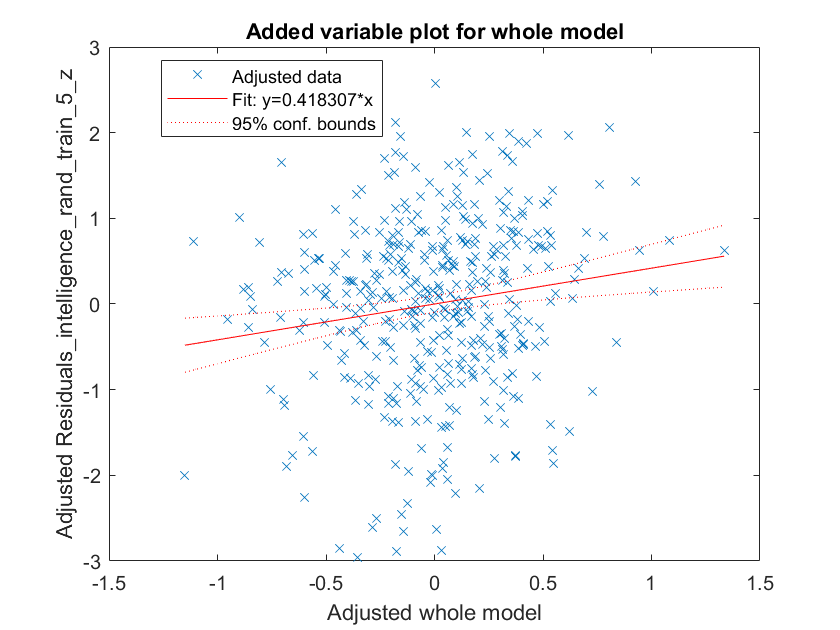

Model_Matrix = [residuals_emotion_pos_train_5_z residuals_emotion_neg_train_5_z residuals_gambling_pos_train_5_z residuals_gambling_neg_train_5_z residuals_language_pos_train_5_z residuals_language_neg_train_5_z residuals_motor_pos_train_5_z residuals_motor_neg_train_5_z residuals_relational_pos_train_5_z residuals_relational_neg_train_5_z residuals_social_pos_train_5_z residuals_social_neg_train_5_z residuals_wm_pos_train_5_z residuals_wm_neg_train_5_z residuals_intelligence_train_5_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_5_z', 'residuals_emotion_neg_train_5_z', 'residuals_gambling_pos_train_5_z', 'residuals_gambling_neg_train_5_z', 'residuals_language_pos_train_5_z', 'residuals_language_neg_train_5_z', 'residuals_motor_pos_train_5_z', 'residuals_motor_neg_train_5_z', 'residuals_relational_pos_train_5_z', 'residuals_relational_neg_train_5_z', 'residuals_social_pos_train_5_z', 'residuals_social_neg_train_5_z', 'residuals_wm_pos_train_5_z', 'residuals_wm_neg_train_5_z','Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2. Predict the intelligence scores in test samples **

1.1. Test Sample 1

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{1,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];


Positive_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_1 = (Positive_all_emotion - Positive_all_pred_emotion_test_1);
residuals_pos_emotion_test_1_z = normalize(residuals_pos_emotion_test_1,"center",c_pos_NMA_emotion_train_1,"scale",s_pos_NMA_emotion_train_1);


Negative_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_1 = (Negative_all_emotion - Negative_all_pred_emotion_test_1);
residuals_neg_emotion_test_1_z = normalize(residuals_neg_emotion_test_1,"center",c_neg_NMA_emotion_train_1,"scale",s_neg_NMA_emotion_train_1);


Positive_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_1 = (Positive_all_gambling - Positive_all_pred_gambling_test_1);
residuals_pos_gambling_test_1_z = normalize(residuals_pos_gambling_test_1,"center",c_pos_NMA_gambling_train_1,"scale",s_pos_NMA_gambling_train_1);


Negative_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_1 = (Negative_all_gambling - Negative_all_pred_gambling_test_1);
residuals_neg_gambling_test_1_z = normalize(residuals_neg_gambling_test_1,"center",c_neg_NMA_gambling_train_1,"scale",s_neg_NMA_gambling_train_1);


Positive_all_pred_language_test_1 = predict(mdl_regress_train_1_language_pos_bcs,confounds);

residuals_pos_language_test_1 = (Positive_all_language - Positive_all_pred_language_test_1);
residuals_pos_language_test_1_z = normalize(residuals_pos_language_test_1,"center",c_pos_NMA_language_train_1,"scale",s_pos_NMA_language_train_1);


Negative_all_pred_language_test_1 = predict(mdl_regress_train_1_language_neg_bcs,confounds);

residuals_neg_language_test_1 = (Negative_all_language - Negative_all_pred_language_test_1);
residuals_neg_language_test_1_z = normalize(residuals_neg_language_test_1,"center",c_neg_NMA_language_train_1,"scale",s_neg_NMA_language_train_1);


Positive_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_pos_bcs,confounds);

residuals_pos_motor_test_1 = (Positive_all_motor - Positive_all_pred_motor_test_1);
residuals_pos_motor_test_1_z = normalize(residuals_pos_motor_test_1,"center",c_pos_NMA_motor_train_1,"scale",s_pos_NMA_motor_train_1);


Negative_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_neg_bcs,confounds);

residuals_neg_motor_test_1 = (Negative_all_motor - Negative_all_pred_motor_test_1);
residuals_neg_motor_test_1_z = normalize(residuals_neg_motor_test_1,"center",c_neg_NMA_motor_train_1,"scale",s_neg_NMA_motor_train_1);



Positive_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_pos_bcs,confounds);

residuals_pos_relational_test_1 = (Positive_all_relational - Positive_all_pred_relational_test_1);
residuals_pos_relational_test_1_z = normalize(residuals_pos_relational_test_1,"center",c_pos_NMA_relational_train_1,"scale",s_pos_NMA_relational_train_1);


Negative_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_neg_bcs,confounds);

residuals_neg_relational_test_1 = (Negative_all_relational - Negative_all_pred_relational_test_1);
residuals_neg_relational_test_1_z = normalize(residuals_neg_relational_test_1,"center",c_neg_NMA_relational_train_1,"scale",s_neg_NMA_relational_train_1);


Positive_all_pred_social_test_1 = predict(mdl_regress_train_1_social_pos_bcs,confounds);

residuals_pos_social_test_1 = (Positive_all_social - Positive_all_pred_social_test_1);
residuals_pos_social_test_1_z = normalize(residuals_pos_social_test_1,"center",c_pos_NMA_social_train_1,"scale",s_pos_NMA_social_train_1);


Negative_all_pred_social_test_1 = predict(mdl_regress_train_1_social_neg_bcs,confounds);

residuals_neg_social_test_1 = (Negative_all_social - Negative_all_pred_social_test_1);
residuals_neg_social_test_1_z = normalize(residuals_neg_social_test_1,"center",c_neg_NMA_social_train_1,"scale",s_neg_NMA_social_train_1);


Positive_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_pos_bcs,confounds);

residuals_pos_wm_test_1 = (Positive_all_wm - Positive_all_pred_wm_test_1);
residuals_pos_wm_test_1_z = normalize(residuals_pos_wm_test_1,"center",c_pos_NMA_wm_train_1,"scale",s_pos_NMA_wm_train_1);


Negative_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_neg_bcs,confounds);

residuals_neg_wm_test_1 = (Negative_all_wm - Negative_all_pred_wm_test_1);
residuals_neg_wm_test_1_z = normalize(residuals_neg_wm_test_1,"center",c_neg_NMA_wm_train_1,"scale",s_neg_NMA_wm_train_1);

Xnew = [residuals_pos_emotion_test_1_z residuals_neg_emotion_test_1_z residuals_pos_gambling_test_1_z residuals_neg_gambling_test_1_z residuals_pos_language_test_1_z residuals_neg_language_test_1_z residuals_pos_motor_test_1_z residuals_neg_motor_test_1_z residuals_pos_relational_test_1_z residuals_neg_relational_test_1_z residuals_pos_social_test_1_z residuals_neg_social_test_1_z residuals_pos_wm_test_1_z residuals_neg_wm_test_1_z];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

1.2. Test Sample 2 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{2,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];


Positive_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_2 = (Positive_all_emotion - Positive_all_pred_emotion_test_2);
residuals_pos_emotion_test_2_z = normalize(residuals_pos_emotion_test_2,"center",c_pos_NMA_emotion_train_2,"scale",s_pos_NMA_emotion_train_2);


Negative_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_2 = (Negative_all_emotion - Negative_all_pred_emotion_test_2);
residuals_neg_emotion_test_2_z = normalize(residuals_neg_emotion_test_2,"center",c_neg_NMA_emotion_train_2,"scale",s_neg_NMA_emotion_train_2);


Positive_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_2 = (Positive_all_gambling - Positive_all_pred_gambling_test_2);
residuals_pos_gambling_test_2_z = normalize(residuals_pos_gambling_test_2,"center",c_pos_NMA_gambling_train_2,"scale",s_pos_NMA_gambling_train_2);


Negative_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_2 = (Negative_all_gambling - Negative_all_pred_gambling_test_2);
residuals_neg_gambling_test_2_z = normalize(residuals_neg_gambling_test_2,"center",c_neg_NMA_gambling_train_2,"scale",s_neg_NMA_gambling_train_2);



Positive_all_pred_language_test_2 = predict(mdl_regress_train_2_language_pos_bcs,confounds);

residuals_pos_language_test_2 = (Positive_all_language - Positive_all_pred_language_test_2);
residuals_pos_language_test_2_z = normalize(residuals_pos_language_test_2,"center",c_pos_NMA_language_train_2,"scale",s_pos_NMA_language_train_2);


Negative_all_pred_language_test_2 = predict(mdl_regress_train_2_language_neg_bcs,confounds);

residuals_neg_language_test_2 = (Negative_all_language - Negative_all_pred_language_test_2);
residuals_neg_language_test_2_z = normalize(residuals_neg_language_test_2,"center",c_neg_NMA_language_train_2,"scale",s_neg_NMA_language_train_2);


Positive_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_pos_bcs,confounds);

residuals_pos_motor_test_2 = (Positive_all_motor - Positive_all_pred_motor_test_2);
residuals_pos_motor_test_2_z = normalize(residuals_pos_motor_test_2,"center",c_pos_NMA_motor_train_2,"scale",s_pos_NMA_motor_train_2);


Negative_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_neg_bcs,confounds);

residuals_neg_motor_test_2 = (Negative_all_motor - Negative_all_pred_motor_test_2);
residuals_neg_motor_test_2_z = normalize(residuals_neg_motor_test_2,"center",c_neg_NMA_motor_train_2,"scale",s_neg_NMA_motor_train_2);


Positive_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_pos_bcs,confounds);

residuals_pos_relational_test_2 = (Positive_all_relational - Positive_all_pred_relational_test_2);
residuals_pos_relational_test_2_z = normalize(residuals_pos_relational_test_2,"center",c_pos_NMA_relational_train_2,"scale",s_pos_NMA_relational_train_2);


Negative_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_neg_bcs,confounds);

residuals_neg_relational_test_2 = (Negative_all_relational - Negative_all_pred_relational_test_2);
residuals_neg_relational_test_2_z = normalize(residuals_neg_relational_test_2,"center",c_neg_NMA_relational_train_2,"scale",s_neg_NMA_relational_train_2);


Positive_all_pred_social_test_2 = predict(mdl_regress_train_2_social_pos_bcs,confounds);

residuals_pos_social_test_2 = (Positive_all_social - Positive_all_pred_social_test_2);
residuals_pos_social_test_2_z = normalize(residuals_pos_social_test_2,"center",c_pos_NMA_social_train_2,"scale",s_pos_NMA_social_train_2);


Negative_all_pred_social_test_2 = predict(mdl_regress_train_2_social_neg_bcs,confounds);

residuals_neg_social_test_2 = (Negative_all_social - Negative_all_pred_social_test_2);
residuals_neg_social_test_2_z = normalize(residuals_neg_social_test_2,"center",c_neg_NMA_social_train_2,"scale",s_neg_NMA_social_train_2);


Positive_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_pos_bcs,confounds);

residuals_pos_wm_test_2 = (Positive_all_wm - Positive_all_pred_wm_test_2);
residuals_pos_wm_test_2_z = normalize(residuals_pos_wm_test_2,"center",c_pos_NMA_wm_train_2,"scale",s_pos_NMA_wm_train_2);


Negative_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_neg_bcs,confounds);

residuals_neg_wm_test_2 = (Negative_all_wm - Negative_all_pred_wm_test_2);
residuals_neg_wm_test_2_z = normalize(residuals_neg_wm_test_2,"center",c_neg_NMA_wm_train_2,"scale",s_neg_NMA_wm_train_2);

Xnew = [residuals_pos_emotion_test_2_z residuals_neg_emotion_test_2_z residuals_pos_gambling_test_2_z residuals_neg_gambling_test_2_z residuals_pos_language_test_2_z residuals_neg_language_test_2_z residuals_pos_motor_test_2_z residuals_neg_motor_test_2_z residuals_pos_relational_test_2_z residuals_neg_relational_test_2_z residuals_pos_social_test_2_z residuals_neg_social_test_2_z residuals_pos_wm_test_2_z residuals_neg_wm_test_2_z];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

1.3. Test Sample 3 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{3,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];


Positive_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_3 = (Positive_all_emotion - Positive_all_pred_emotion_test_3);
residuals_pos_emotion_test_3_z = normalize(residuals_pos_emotion_test_3,"center",c_pos_NMA_emotion_train_3,"scale",s_pos_NMA_emotion_train_3);


Negative_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_3 = (Negative_all_emotion - Negative_all_pred_emotion_test_3);
residuals_neg_emotion_test_3_z = normalize(residuals_neg_emotion_test_3,"center",c_neg_NMA_emotion_train_3,"scale",s_neg_NMA_emotion_train_3);



Positive_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_3 = (Positive_all_gambling - Positive_all_pred_gambling_test_3);
residuals_pos_gambling_test_3_z = normalize(residuals_pos_gambling_test_3,"center",c_pos_NMA_gambling_train_3,"scale",s_pos_NMA_gambling_train_3);



Negative_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_3 = (Negative_all_gambling - Negative_all_pred_gambling_test_3);
residuals_neg_gambling_test_3_z = normalize(residuals_neg_gambling_test_3,"center",c_neg_NMA_gambling_train_3,"scale",s_neg_NMA_gambling_train_3);


Positive_all_pred_language_test_3 = predict(mdl_regress_train_3_language_pos_bcs,confounds);

residuals_pos_language_test_3 = (Positive_all_language - Positive_all_pred_language_test_3);
residuals_pos_language_test_3_z = normalize(residuals_pos_language_test_3,"center",c_pos_NMA_language_train_3,"scale",s_pos_NMA_language_train_3);


Negative_all_pred_language_test_3 = predict(mdl_regress_train_3_language_neg_bcs,confounds);

residuals_neg_language_test_3 = (Negative_all_language - Negative_all_pred_language_test_3);
residuals_neg_language_test_3_z = normalize(residuals_neg_language_test_3,"center",c_neg_NMA_language_train_3,"scale",s_neg_NMA_language_train_3);


Positive_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_pos_bcs,confounds);

residuals_pos_motor_test_3 = (Positive_all_motor - Positive_all_pred_motor_test_3);
residuals_pos_motor_test_3_z = normalize(residuals_pos_motor_test_3,"center",c_pos_NMA_motor_train_3,"scale",s_pos_NMA_motor_train_3);


Negative_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_neg_bcs,confounds);

residuals_neg_motor_test_3 = (Negative_all_motor - Negative_all_pred_motor_test_3);
residuals_neg_motor_test_3_z = normalize(residuals_neg_motor_test_3,"center",c_neg_NMA_motor_train_3,"scale",s_neg_NMA_motor_train_3);

Positive_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_pos_bcs,confounds);

residuals_pos_relational_test_3 = (Positive_all_relational - Positive_all_pred_relational_test_3);
residuals_pos_relational_test_3_z = normalize(residuals_pos_relational_test_3,"center",c_pos_NMA_relational_train_3,"scale",s_pos_NMA_relational_train_3);


Negative_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_neg_bcs,confounds);

residuals_neg_relational_test_3 = (Negative_all_relational - Negative_all_pred_relational_test_3);
residuals_neg_relational_test_3_z = normalize(residuals_neg_relational_test_3,"center",c_neg_NMA_relational_train_3,"scale",s_neg_NMA_relational_train_3);


Positive_all_pred_social_test_3 = predict(mdl_regress_train_3_social_pos_bcs,confounds);

residuals_pos_social_test_3 = (Positive_all_social - Positive_all_pred_social_test_3);
residuals_pos_social_test_3_z = normalize(residuals_pos_social_test_3,"center",c_pos_NMA_social_train_3,"scale",s_pos_NMA_social_train_3);


Negative_all_pred_social_test_3 = predict(mdl_regress_train_3_social_neg_bcs,confounds);

residuals_neg_social_test_3 = (Negative_all_social - Negative_all_pred_social_test_3);
residuals_neg_social_test_3_z = normalize(residuals_neg_social_test_3,"center",c_neg_NMA_social_train_3,"scale",s_neg_NMA_social_train_3);



Positive_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_pos_bcs,confounds);

residuals_pos_wm_test_3 = (Positive_all_wm - Positive_all_pred_wm_test_3);
residuals_pos_wm_test_3_z = normalize(residuals_pos_wm_test_3,"center",c_pos_NMA_wm_train_3,"scale",s_pos_NMA_wm_train_3);


Negative_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_neg_bcs,confounds);

residuals_neg_wm_test_3 = (Negative_all_wm - Negative_all_pred_wm_test_3);
residuals_neg_wm_test_3_z = normalize(residuals_neg_wm_test_3,"center",c_neg_NMA_wm_train_3,"scale",s_neg_NMA_wm_train_3);

Xnew = [residuals_pos_emotion_test_3_z residuals_neg_emotion_test_3_z residuals_pos_gambling_test_3_z residuals_neg_gambling_test_3_z residuals_pos_language_test_3_z residuals_neg_language_test_3_z residuals_pos_motor_test_3_z residuals_neg_motor_test_3_z residuals_pos_relational_test_3_z residuals_neg_relational_test_3_z residuals_pos_social_test_3_z residuals_neg_social_test_3_z residuals_pos_wm_test_3_z residuals_neg_wm_test_3_z];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);

[r,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

1.4. Test Sample 4 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];


Positive_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_4 = (Positive_all_emotion - Positive_all_pred_emotion_test_4);
residuals_pos_emotion_test_4_z = normalize(residuals_pos_emotion_test_4,"center",c_pos_NMA_emotion_train_4,"scale",s_pos_NMA_emotion_train_4);


Negative_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_4 = (Negative_all_emotion - Negative_all_pred_emotion_test_4);
residuals_neg_emotion_test_4_z = normalize(residuals_neg_emotion_test_4,"center",c_neg_NMA_emotion_train_4,"scale",s_neg_NMA_emotion_train_4);


Positive_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_4 = (Positive_all_gambling - Positive_all_pred_gambling_test_4);
residuals_pos_gambling_test_4_z = normalize(residuals_pos_gambling_test_4,"center",c_pos_NMA_gambling_train_4,"scale",s_pos_NMA_gambling_train_4);



Negative_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_4 = (Negative_all_gambling - Negative_all_pred_gambling_test_4);
residuals_neg_gambling_test_4_z = normalize(residuals_neg_gambling_test_4,"center",c_neg_NMA_gambling_train_4,"scale",s_neg_NMA_gambling_train_4);


Positive_all_pred_language_test_4 = predict(mdl_regress_train_4_language_pos_bcs,confounds);

residuals_pos_language_test_4 = (Positive_all_language - Positive_all_pred_language_test_4);
residuals_pos_language_test_4_z = normalize(residuals_pos_language_test_4,"center",c_pos_NMA_language_train_4,"scale",s_pos_NMA_language_train_4);


Negative_all_pred_language_test_4 = predict(mdl_regress_train_4_language_neg_bcs,confounds);

residuals_neg_language_test_4 = (Negative_all_language - Negative_all_pred_language_test_4);
residuals_neg_language_test_4_z = normalize(residuals_neg_language_test_4,"center",c_neg_NMA_language_train_4,"scale",s_neg_NMA_language_train_4);


Positive_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_pos_bcs,confounds);

residuals_pos_motor_test_4 = (Positive_all_motor - Positive_all_pred_motor_test_4);
residuals_pos_motor_test_4_z = normalize(residuals_pos_motor_test_4,"center",c_pos_NMA_motor_train_4,"scale",s_pos_NMA_motor_train_4);



Negative_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_neg_bcs,confounds);

residuals_neg_motor_test_4 = (Negative_all_motor - Negative_all_pred_motor_test_4);
residuals_neg_motor_test_4_z = normalize(residuals_neg_motor_test_4,"center",c_neg_NMA_motor_train_4,"scale",s_neg_NMA_motor_train_4);


Positive_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_pos_bcs,confounds);

residuals_pos_relational_test_4 = (Positive_all_relational - Positive_all_pred_relational_test_4);
residuals_pos_relational_test_4_z = normalize(residuals_pos_relational_test_4,"center",c_pos_NMA_relational_train_4,"scale",s_pos_NMA_relational_train_4);


Negative_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_neg_bcs,confounds);

residuals_neg_relational_test_4 = (Negative_all_relational - Negative_all_pred_relational_test_4);
residuals_neg_relational_test_4_z = normalize(residuals_neg_relational_test_4,"center",c_neg_NMA_relational_train_4,"scale",s_neg_NMA_relational_train_4);


Positive_all_pred_social_test_4 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_4 = (Positive_all_social - Positive_all_pred_social_test_4);
residuals_pos_social_test_4_z = normalize(residuals_pos_social_test_4,"center",c_pos_NMA_social_train_4,"scale",s_pos_NMA_social_train_4);


Negative_all_pred_social_test_4 = predict(mdl_regress_train_4_social_neg_bcs,confounds);

residuals_neg_social_test_4 = (Negative_all_social - Negative_all_pred_social_test_4);
residuals_neg_social_test_4_z = normalize(residuals_neg_social_test_4,"center",c_neg_NMA_social_train_4,"scale",s_neg_NMA_social_train_4);


Positive_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_pos_bcs,confounds);

residuals_pos_wm_test_4 = (Positive_all_wm - Positive_all_pred_wm_test_4);
residuals_pos_wm_test_4_z = normalize(residuals_pos_wm_test_4,"center",c_pos_NMA_wm_train_4,"scale",s_pos_NMA_wm_train_4);


Negative_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_neg_bcs,confounds);

residuals_neg_wm_test_4 = (Negative_all_wm - Negative_all_pred_wm_test_4);
residuals_neg_wm_test_4_z = normalize(residuals_neg_wm_test_4,"center",c_neg_NMA_wm_train_4,"scale",s_neg_NMA_wm_train_4);

Xnew = [residuals_pos_emotion_test_4_z residuals_neg_emotion_test_4_z residuals_pos_gambling_test_4_z residuals_neg_gambling_test_4_z residuals_pos_language_test_4_z residuals_neg_language_test_4_z residuals_pos_motor_test_4_z residuals_neg_motor_test_4_z residuals_pos_relational_test_4_z residuals_neg_relational_test_4_z residuals_pos_social_test_4_z residuals_neg_social_test_4_z residuals_pos_wm_test_4_z residuals_neg_wm_test_4_z];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);

[r,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

1.5. Test Sample 5 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];
Intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - Intelligence_pred_test_5);
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{5,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];



Positive_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_5 = (Positive_all_emotion - Positive_all_pred_emotion_test_5);
residuals_pos_emotion_test_5_z = normalize(residuals_pos_emotion_test_5,"center",c_pos_NMA_emotion_train_5,"scale",s_pos_NMA_emotion_train_5);


Negative_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_5 = (Negative_all_emotion - Negative_all_pred_emotion_test_5);
residuals_neg_emotion_test_5_z = normalize(residuals_neg_emotion_test_5,"center",c_neg_NMA_emotion_train_5,"scale",s_neg_NMA_emotion_train_5);


Positive_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_5 = (Positive_all_gambling - Positive_all_pred_gambling_test_5);
residuals_pos_gambling_test_5_z = normalize(residuals_pos_gambling_test_5,"center",c_pos_NMA_gambling_train_5,"scale",s_pos_NMA_gambling_train_5);


Negative_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_5 = (Negative_all_gambling - Negative_all_pred_gambling_test_5);
residuals_neg_gambling_test_5_z = normalize(residuals_neg_gambling_test_5,"center",c_neg_NMA_gambling_train_5,"scale",s_neg_NMA_gambling_train_5);


Positive_all_pred_language_test_5 = predict(mdl_regress_train_5_language_pos_bcs,confounds);

residuals_pos_language_test_5 = (Positive_all_language - Positive_all_pred_language_test_5);
residuals_pos_language_test_5_z = normalize(residuals_pos_language_test_5,"center",c_pos_NMA_language_train_5,"scale",s_pos_NMA_language_train_5);


Negative_all_pred_language_test_5 = predict(mdl_regress_train_5_language_neg_bcs,confounds);

residuals_neg_language_test_5 = (Negative_all_language - Negative_all_pred_language_test_5);
residuals_neg_language_test_5_z = normalize(residuals_neg_language_test_5,"center",c_neg_NMA_language_train_5,"scale",s_neg_NMA_language_train_5);


Positive_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_pos_bcs,confounds);

residuals_pos_motor_test_5 = (Positive_all_motor - Positive_all_pred_motor_test_5);
residuals_pos_motor_test_5_z = normalize(residuals_pos_motor_test_5,"center",c_pos_NMA_motor_train_5,"scale",s_pos_NMA_motor_train_5);


Negative_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_neg_bcs,confounds);

residuals_neg_motor_test_5 = (Negative_all_motor - Negative_all_pred_motor_test_5);
residuals_neg_motor_test_5_z = normalize(residuals_neg_motor_test_5,"center",c_neg_NMA_motor_train_5,"scale",s_neg_NMA_motor_train_5);


Positive_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_pos_bcs,confounds);

residuals_pos_relational_test_5 = (Positive_all_relational - Positive_all_pred_relational_test_5);
residuals_pos_relational_test_5_z = normalize(residuals_pos_relational_test_5,"center",c_pos_NMA_relational_train_5,"scale",s_pos_NMA_relational_train_5);


Negative_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_neg_bcs,confounds);

residuals_neg_relational_test_5 = (Negative_all_relational - Negative_all_pred_relational_test_5);
residuals_neg_relational_test_5_z = normalize(residuals_neg_relational_test_5,"center",c_neg_NMA_relational_train_5,"scale",s_neg_NMA_relational_train_5);


Positive_all_pred_social_test_5 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_5 = (Positive_all_social - Positive_all_pred_social_test_5);
residuals_pos_social_test_5_z = normalize(residuals_pos_social_test_5,"center",c_pos_NMA_social_train_5,"scale",s_pos_NMA_social_train_5);


Negative_all_pred_social_test_5 = predict(mdl_regress_train_5_social_neg_bcs,confounds);

residuals_neg_social_test_5 = (Negative_all_social - Negative_all_pred_social_test_5);
residuals_neg_social_test_5_z = normalize(residuals_neg_social_test_5,"center",c_neg_NMA_social_train_5,"scale",s_neg_NMA_social_train_5);


Positive_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_pos_bcs,confounds);

residuals_pos_wm_test_5 = (Positive_all_wm - Positive_all_pred_wm_test_5);
residuals_pos_wm_test_5_z = normalize(residuals_pos_wm_test_5,"center",c_pos_NMA_wm_train_5,"scale",s_pos_NMA_wm_train_5);


Negative_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_neg_bcs,confounds);

residuals_neg_wm_test_5 = (Negative_all_wm - Negative_all_pred_wm_test_5);
residuals_neg_wm_test_5_z = normalize(residuals_neg_wm_test_5,"center",c_neg_NMA_wm_train_5,"scale",s_neg_NMA_wm_train_5);

Xnew = [residuals_pos_emotion_test_5_z residuals_neg_emotion_test_5_z residuals_pos_gambling_test_5_z residuals_neg_gambling_test_5_z residuals_pos_language_test_5_z residuals_neg_language_test_5_z residuals_pos_motor_test_5_z residuals_neg_motor_test_5_z residuals_pos_relational_test_5_z residuals_neg_relational_test_5_z residuals_pos_social_test_5_z residuals_neg_social_test_5_z residuals_pos_wm_test_5_z residuals_neg_wm_test_5_z];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3. Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_rand; ypred2_rand; ypred3_rand; ypred4_rand; ypred5_rand];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho_final,pval_final] = corr(predicted_scores,actual_scores);

**4. Save rho_final & pval_final for permutation test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = rho_final;
Permutation_test_all_cross_val_rounds_pval{cross_validation_round, permutation_test_round} = pval_final;

End permutation test

end

end

**Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations =     0.2336
    0.2695
    0.2527
    0.2764
    0.2468
    0.2613
    0.2555
    0.2470
    0.2775
    0.2606



all_rhos_final_correlations_z_scores = atanh(all_rhos_final_correlations);

mean_all_rhos_final_correlations_z_score = mean(all_rhos_final_correlations_z_scores);

mean_all_rhos_final_correlations_final = tanh(mean_all_rhos_final_correlations_z_score)

mean_all_rhos_final_correlations_final = 0.2500



Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho);


find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations_final)


ans =

  0×1 empty double column vector

